# Channel Verification live scirpt



clear; close all; clc;




## Section 1: Verifying Rayleigh Fading

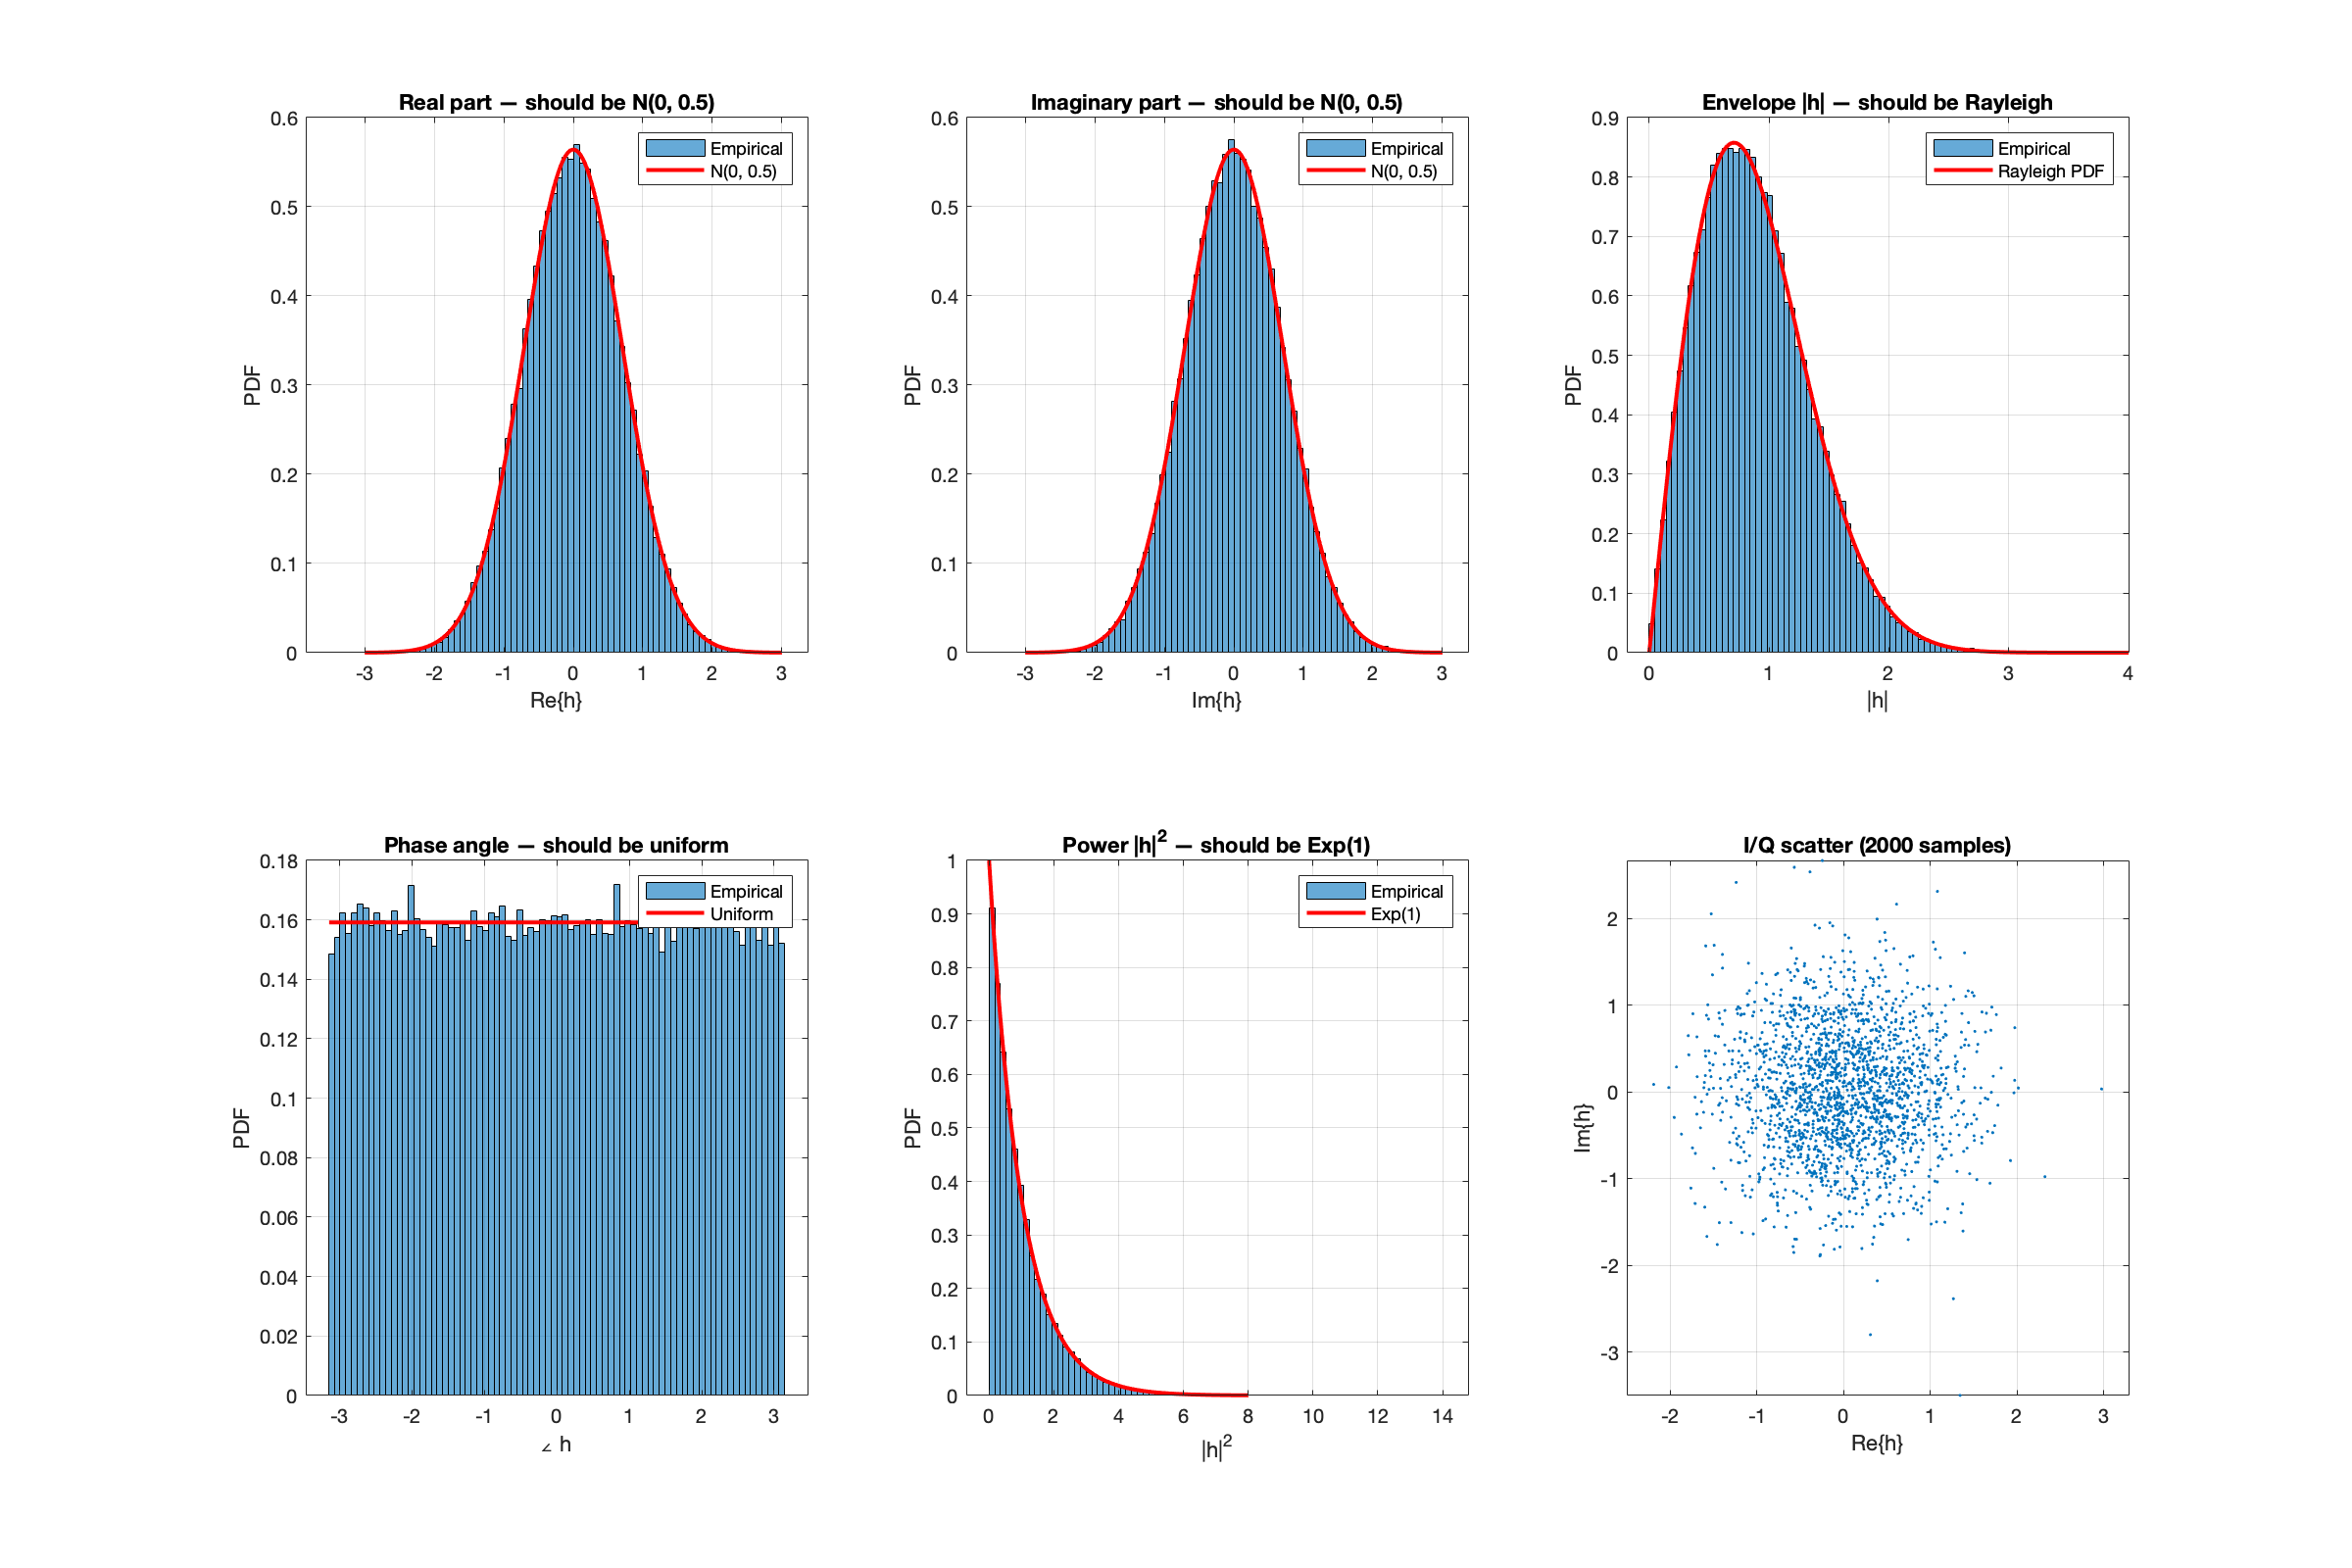



N_samples = 100000;
% Generate CN(0,1) samples
h = Rayleigh_model(N_samples);
 
% Extract components
h_real = real(h);
h_imag = imag(h);
h_envelope = abs(h);
h_phase = angle(h);
h_power = abs(h).^2;
 
% --- Verify real part: should be N(0, 0.5) ---
figure('Name', 'Section 1: Rayleigh Verification', 'Position', [100 100 1200 800]);
 
subplot(2,3,1);
histogram(h_real, 80, 'Normalization', 'pdf'); hold on;
x_range = linspace(-3, 3, 200);
plot(x_range, normpdf(x_range, 0, sqrt(0.5)), 'r-', 'LineWidth', 2);
title('Real part — should be N(0, 0.5)');
xlabel('Re\{h\}'); ylabel('PDF');
legend('Empirical', 'N(0, 0.5)');
grid on;
 
% --- Verify imaginary part: should be N(0, 0.5) ---
subplot(2,3,2);
histogram(h_imag, 80, 'Normalization', 'pdf'); hold on;
plot(x_range, normpdf(x_range, 0, sqrt(0.5)), 'r-', 'LineWidth', 2);
title('Imaginary part — should be N(0, 0.5)');
xlabel('Im\{h\}'); ylabel('PDF');
legend('Empirical', 'N(0, 0.5)');
grid on;
 
% --- Verify envelope: should be Rayleigh ---
subplot(2,3,3);
histogram(h_envelope, 80, 'Normalization', 'pdf'); hold on;
r_range = linspace(0, 4, 200);
rayleigh_pdf = 2 * r_range .* exp(-r_range.^2);  % sigma^2 = 1/2
plot(r_range, rayleigh_pdf, 'r-', 'LineWidth', 2);
title('Envelope |h| — should be Rayleigh');
xlabel('|h|'); ylabel('PDF');
legend('Empirical', 'Rayleigh PDF');
grid on;
 
% --- Verify phase: should be uniform [-pi, pi] ---
subplot(2,3,4);
histogram(h_phase, 80, 'Normalization', 'pdf'); hold on;
plot([-pi pi], [1/(2*pi) 1/(2*pi)], 'r-', 'LineWidth', 2);
title('Phase angle — should be uniform');
xlabel('\angle h'); ylabel('PDF');
legend('Empirical', 'Uniform');
grid on;
 
% --- Verify power: should be exponential (mean=1) ---
subplot(2,3,5);
histogram(h_power, 80, 'Normalization', 'pdf'); hold on;
p_range = linspace(0, 8, 200);
plot(p_range, exp(-p_range), 'r-', 'LineWidth', 2);
title('Power |h|^2 — should be Exp(1)');
xlabel('|h|^2'); ylabel('PDF');
legend('Empirical', 'Exp(1)');
grid on;
 
% --- Scatter plot: I/Q plane ---
subplot(2,3,6);
plot(real(h(1:2000)), imag(h(1:2000)), '.', 'MarkerSize', 2);
axis equal; grid on;
title('I/Q scatter (2000 samples)');
xlabel('Re\{h\}'); ylabel('Im\{h\}');

 
% Print statistics
fprintf('=== SECTION 1: Rayleigh Verification ===\n');

=== SECTION 1: Rayleigh Verification ===


fprintf('Mean of Re{h}:     %.4f (should be ~0)\n', mean(h_real));

Mean of Re{h}:     -0.0013 (should be ~0)


fprintf('Var of Re{h}:      %.4f (should be ~0.5)\n', var(h_real));

Var of Re{h}:      0.5017 (should be ~0.5)


fprintf('Mean of |h|^2:     %.4f (should be ~1)\n', mean(h_power));

Mean of |h|^2:     0.9997 (should be ~1)


fprintf('Var of |h|^2:      %.4f (should be ~1)\n', var(h_power));

Var of |h|^2:      1.0032 (should be ~1)


fprintf('\n');


## Rician Fading

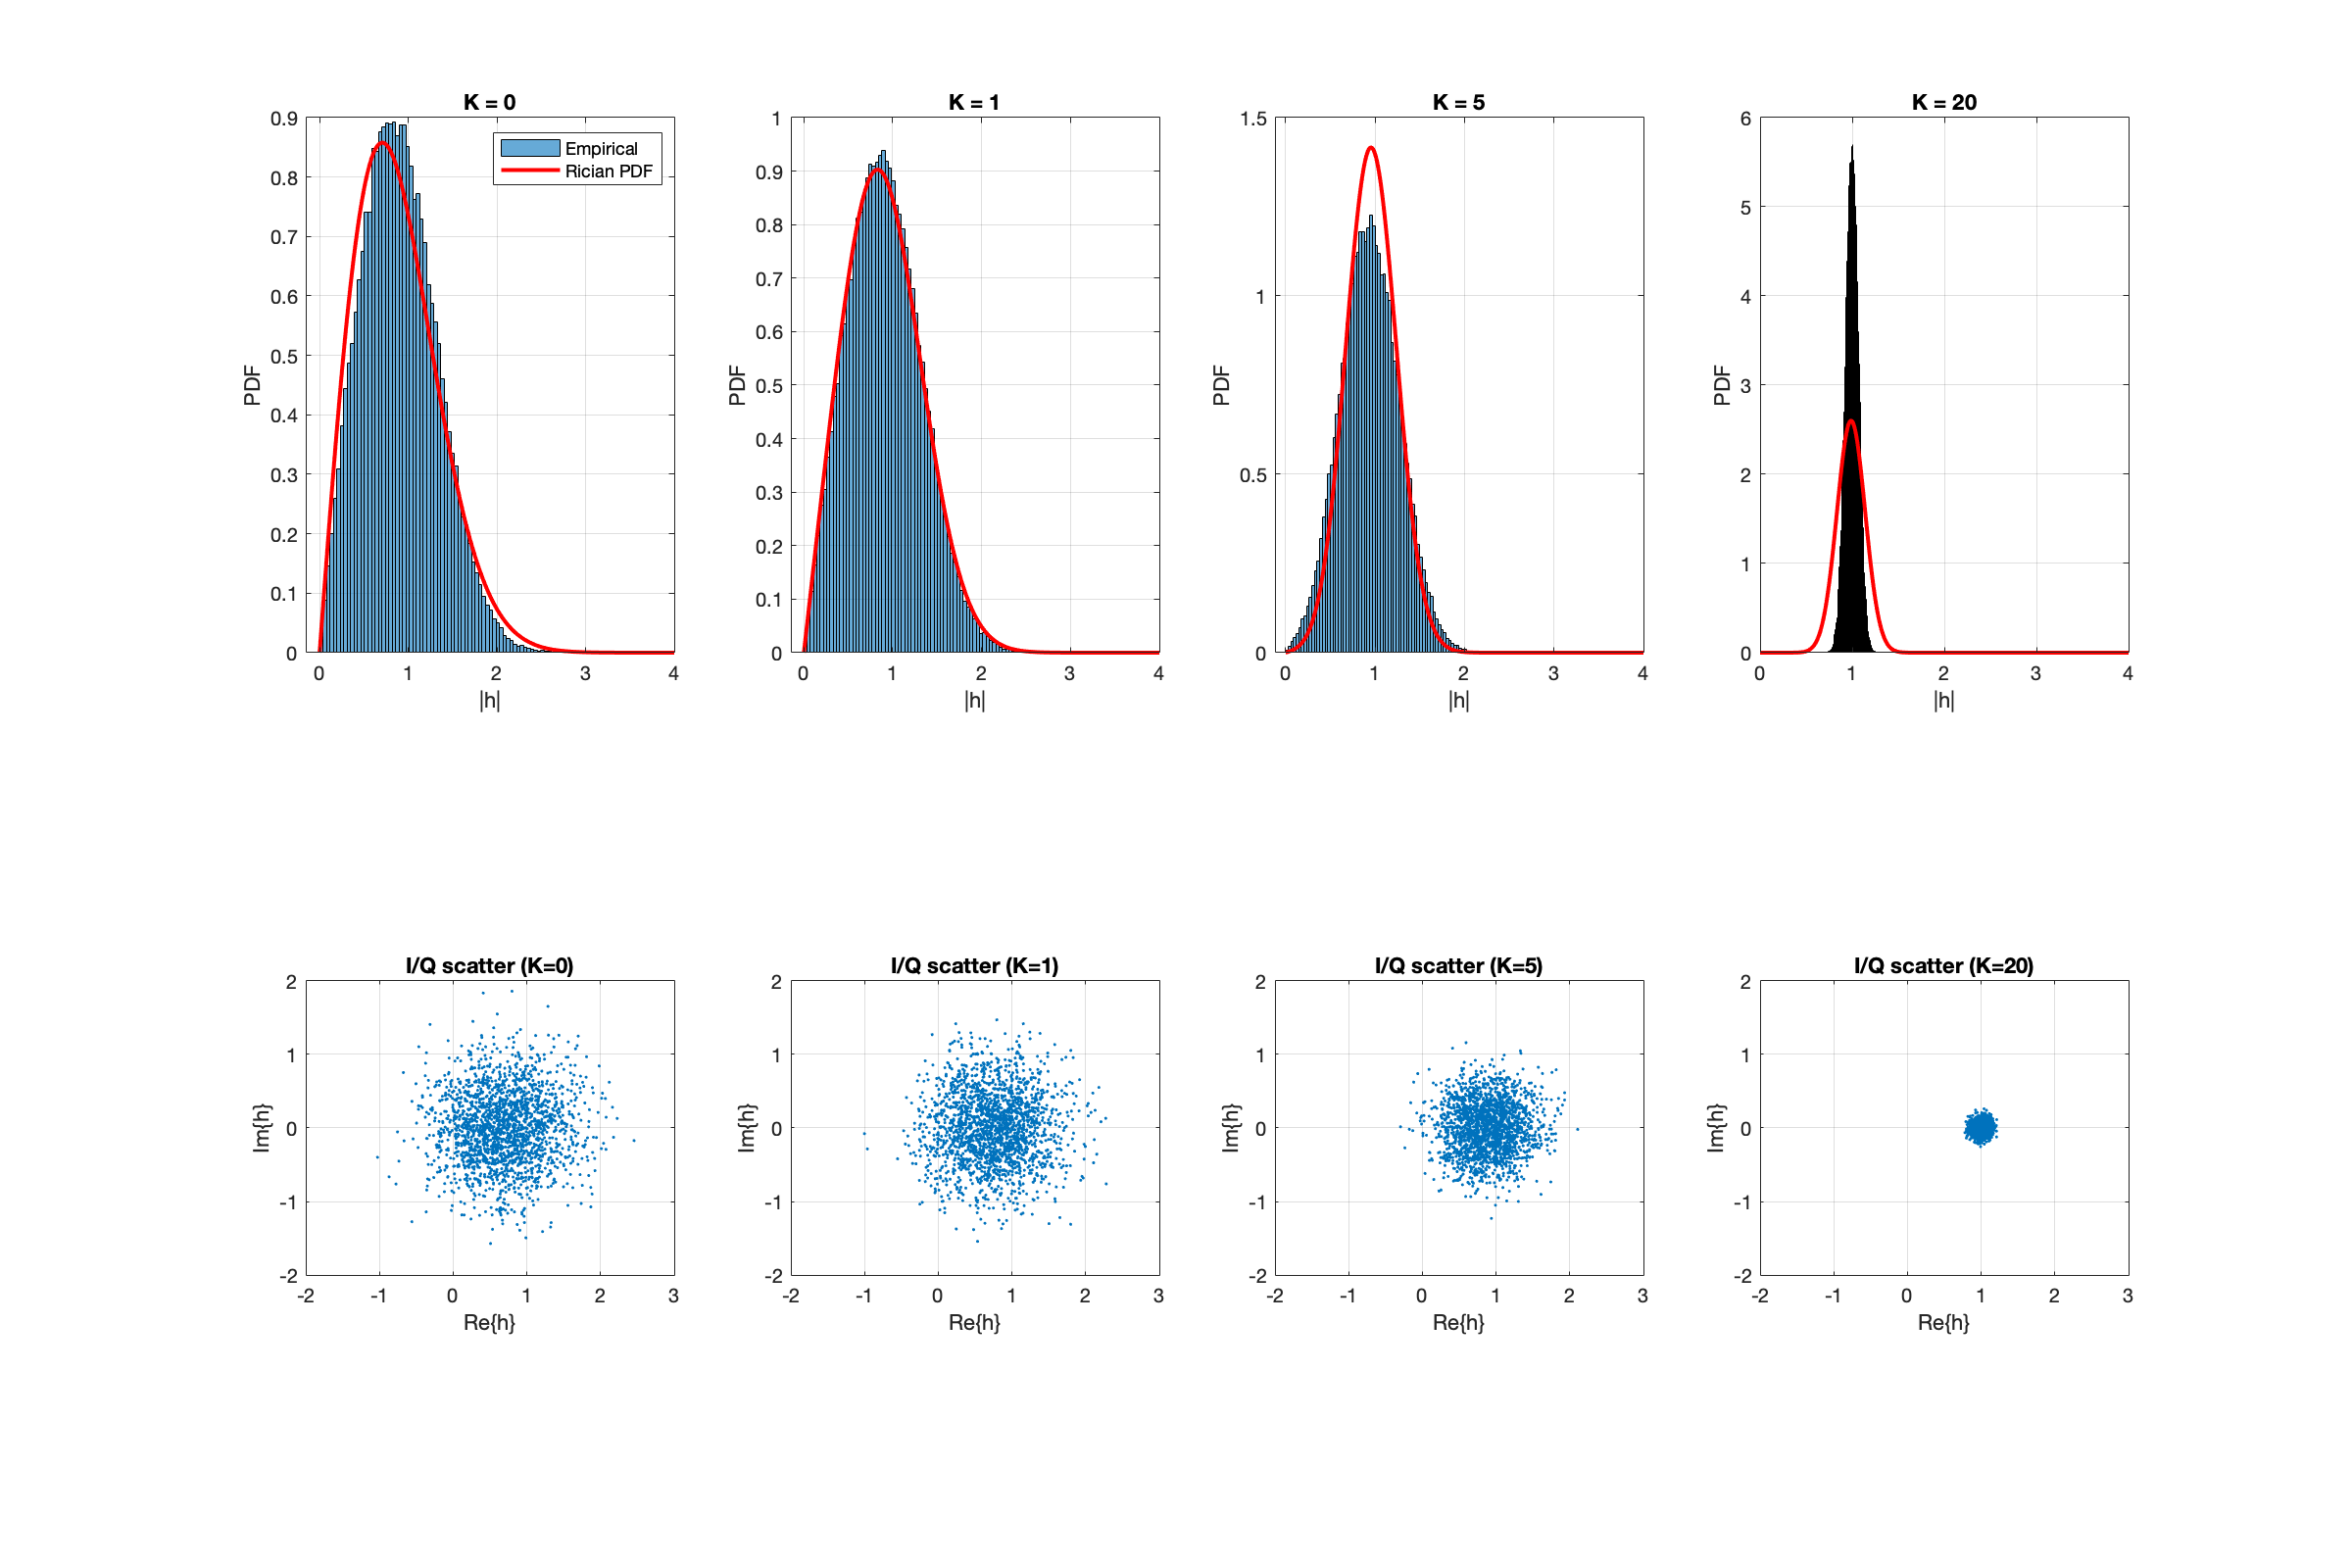

h =    0.2668 - 0.7584i  -0.1418 + 0.0896i   0.7755 + 0.1337i  -0.7750 - 0.7597i   1.9670 + 0.2105i   1.6396 + 0.7172i   1.0730 - 0.6743i   1.2598 - 0.1835i   1.3464 - 0.1337i   0.6404 + 0.6950i   0.8655 - 0.4055i   0.3956 - 0.0882i   0.5116 + 0.3006i  -0.3371 - 0.4951i   1.0123 + 0.8437i   1.4167 - 0.2446i   1.0026 - 0.2203i   0.1825 + 0.6457i   0.6727 - 1.3001i   1.1319 + 0.0199i   0.1663 + 0.3693i   0.6358 + 0.0981i   0.8358 + 0.3273i   1.5155 + 0.0625i   0.1035 - 1.0035i   0.6758 + 0.0810i   0.2975 + 0.2849i   0.2119 - 0.0625i   0.3463 - 0.7343i   1.3325 + 1.0238i   0.0638 - 0.1154i   1.4845 - 0.2776i  -0.4178 + 0.4379i   0.5722 + 0.1638i   1.0705 - 0.4056i   1.2504 + 0.3833i   0.4646 + 0.0863i   0.8913 - 0.1717i   0.9971 - 0.8170i   0.7904 + 0.2988i   1.3873 + 0.0931i   1.2085 + 0.5834i   0.1618 + 0.3975i   0.5305 - 0.4061i   0.3641 - 0.4473i  -0.0792 - 0.0232i   0.3043 - 0.4622i   0.7261 + 0.6579i  -0.3130 + 1.4049i   1.6343 + 0.1370i


h =    0.2059 + 0.0415i   0.7682 + 0.7777i  -0.0160 - 0.3419i   0.5958 + 0.4905i   0.9752 - 0.9938i   0.9241 - 0.2944i   1.0570 - 0.1282i   1.0793 + 0.2182i   0.2667 - 0.1808i   0.6343 - 0.1589i   1.1657 + 0.0986i  -0.0280 + 0.3305i   1.1816 - 0.2885i   0.0532 - 0.9964i   0.0770 + 0.2277i   1.7320 + 0.9594i   1.1161 + 0.0956i   0.6812 - 0.5943i   0.5945 + 0.4203i   1.1660 - 0.1904i   0.0077 + 0.5251i   0.2722 + 0.7254i   0.6288 - 0.9468i  -0.0172 - 0.0889i   0.7243 - 0.8170i   0.5825 - 0.3395i   1.2399 + 0.2215i   0.6900 + 0.2275i   0.7315 + 0.1924i   0.3058 + 0.0303i   0.7277 - 0.2138i   1.1249 + 0.3294i   0.5335 + 0.5491i   0.1808 - 0.3489i   0.2425 - 0.2570i   0.9914 + 0.4254i   0.6953 + 0.2450i   1.1088 - 0.5417i   0.2504 + 0.3441i   0.5268 + 0.7987i   1.2615 - 0.6136i   1.1256 - 0.4099i   1.1615 - 0.0197i   0.9685 - 0.0147i   0.8962 - 0.5768i   0.9341 - 0.4222i   1.7432 - 0.5128i   1.5277 - 0.1543i   0.8159 - 0.3997i   1.1225 + 0.2482i


h =    0.9968 + 0.3820i   0.3730 - 0.2421i   0.5644 + 0.1553i   0.2542 + 0.3188i   1.1904 + 0.0035i   0.8539 - 0.1780i   0.3196 - 0.2155i   0.6828 - 0.7891i   0.8369 - 0.1289i   1.0062 - 0.2549i   0.9623 - 0.1211i   0.4921 + 0.4245i   1.1304 - 0.0126i   0.3120 - 0.1338i   1.2838 - 0.6643i   0.3388 - 0.2098i   0.6598 + 0.2685i   0.9139 - 0.3895i   1.4227 - 0.3146i   1.6342 + 0.2151i   0.9931 + 0.1034i   1.1014 - 0.2509i   1.1751 + 0.0526i   0.7039 + 0.4294i   0.7098 - 0.3277i   1.0878 - 0.0512i   1.0993 - 0.6510i   0.6479 + 0.0492i   0.9156 + 0.2552i   1.1634 - 0.6091i   1.2968 + 0.3483i   0.6931 + 0.4499i   1.0866 + 0.3650i   1.4227 - 0.5117i   1.8355 + 0.2667i   0.3651 - 0.4405i   0.9002 + 0.0610i   1.0180 + 0.2370i   0.3625 + 0.0127i   1.5381 - 0.1645i   0.9675 + 0.0177i   1.1155 + 0.2481i   0.9581 - 0.4135i   0.5389 + 0.2513i   1.1507 - 0.2725i   1.2484 - 0.2212i   1.0901 + 0.0947i   1.1426 - 0.4563i   0.8349 + 0.1573i   1.0782 + 0.0702i


h =    1.0486 - 0.0045i   0.9787 + 0.0008i   0.8104 - 0.1014i   1.0470 - 0.1039i   1.0058 - 0.0272i   1.0383 + 0.2602i   0.8925 + 0.0061i   1.0190 - 0.0905i   1.0451 - 0.0064i   1.0746 - 0.1075i   0.9726 - 0.0577i   0.9666 - 0.0341i   1.2086 - 0.1214i   0.9963 - 0.0485i   0.9855 - 0.1383i   0.8457 - 0.1584i   0.9703 - 0.0228i   1.0012 - 0.0626i   1.1002 + 0.1445i   0.9974 + 0.0274i   1.0935 - 0.0955i   1.0881 - 0.0284i   1.0533 + 0.0697i   1.1059 - 0.1428i   0.9967 - 0.0681i   1.0519 - 0.0974i   1.0208 - 0.0185i   1.0036 - 0.0590i   0.9628 - 0.1487i   0.9047 - 0.0018i   1.0180 + 0.0351i   1.0226 + 0.0331i   1.0657 - 0.1030i   1.0197 - 0.0179i   1.0167 - 0.0154i   0.9690 - 0.0864i   0.9600 - 0.1718i   1.0034 + 0.0045i   0.9365 + 0.1006i   0.9746 - 0.0850i   1.1253 + 0.0418i   0.9327 - 0.0213i   0.9915 - 0.0447i   1.0039 + 0.0125i   0.8981 + 0.0182i   0.9891 + 0.0293i   0.9926 + 0.0247i   1.1362 + 0.0243i   1.0883 + 0.0958i   0.9470 + 0.0298i



N_samples = 100000;
K_values = [0, 1, 5, 20];  % different K-factors
 
figure('Name', 'Section 1b: Rician Verification', 'Position', [100 100 1200 800]);
 
for idx = 1:length(K_values)
    K = K_values(idx);
    
    % Generate Rician samples
    h = Rician_model(K,N_samples)
    
    h_envelope = abs(h);
    
    % Theoretical Rician PDF
    r = linspace(0, 4, 500);
    nu = sqrt(K/(K+1));  % LOS amplitude after normalization
    sigma2 = 1/(2*(K+1));  % scatter variance per dimension
    % Rician PDF: p(r) = (r/sigma2) * exp(-(r^2 + nu^2)/(2*sigma2)) * I0(r*nu/sigma2)
    rice_pdf = (r / sigma2) .* exp(-(r.^2 + nu^2) / (2*sigma2)) .* besseli(0, r*nu/sigma2);
    
    % Plot
    subplot(2, length(K_values), idx);
    histogram(h_envelope, 80, 'Normalization', 'pdf'); hold on;
    plot(r, rice_pdf, 'r-', 'LineWidth', 2);
    title(sprintf('K = %g', K));
    xlabel('|h|'); ylabel('PDF');
    if idx == 1
        legend('Empirical', 'Rician PDF');
    end
    grid on;
    
    % I/Q scatter
    subplot(2, length(K_values), idx + length(K_values));
    plot(real(h(1:2000)), imag(h(1:2000)), '.', 'MarkerSize', 2);
    axis equal; grid on;
    title(sprintf('I/Q scatter (K=%g)', K));
    xlabel('Re\{h\}'); ylabel('Im\{h\}');
    xlim([-2 3]); ylim([-2 2]);
end

 
fprintf('=== SECTION 1b: Rician Verification ===\n');

=== SECTION 1b: Rician Verification ===


for idx = 1:length(K_values)
    K = K_values(idx);
    h_LOS = 1;
    h_scatter = sqrt(0.5) * (randn(N_samples,1) + 1j*randn(N_samples,1));
    h = sqrt(K/(K+1)) * h_LOS + sqrt(1/(K+1)) * h_scatter;
    fprintf('K = %2d: E[|h|^2] = %.4f (should be ~1), mean |h| = %.4f\n', ...
        K, mean(abs(h).^2), mean(abs(h)));
end

K =  0: E[|h|^2] = 0.9997 (should be ~1), mean |h| = 0.8858
K =  1: E[|h|^2] = 1.0001 (should be ~1), mean |h| = 0.9065
K =  5: E[|h|^2] = 1.0032 (should be ~1), mean |h| = 0.9615
K = 20: E[|h|^2] = 1.0006 (should be ~1), mean |h| = 0.9885


fprintf('K=0 is Rayleigh. As K grows, distribution concentrates around |h|=1 (LOS dominates).\n');

K=0 is Rayleigh. As K grows, distribution concentrates around |h|=1 (LOS dominates).


fprintf('\n');

## Exponential Power Delay Profile

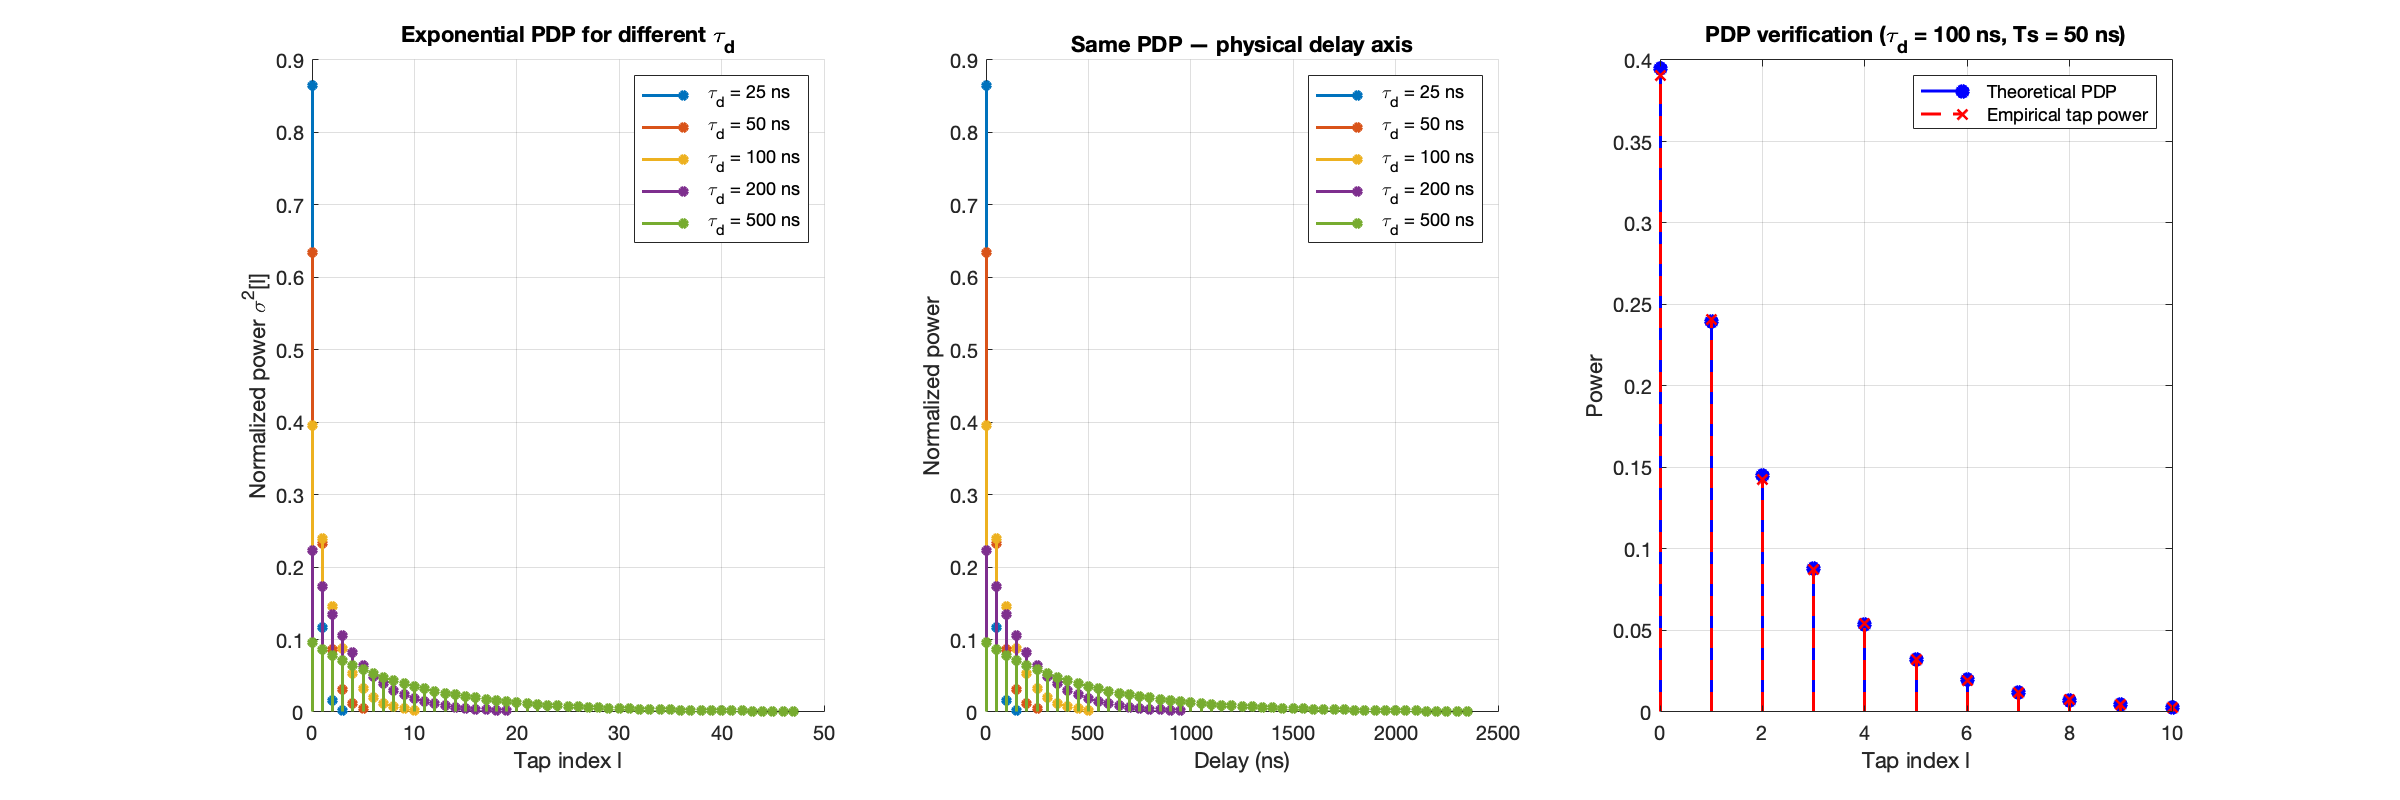




Ts = 50e-9;  % 50 ns sampling period (example: 20 MHz bandwidth)
 
tau_values_ns = [25, 50, 100, 200, 500];  % RMS delay spread in ns
 
figure('Name', 'Section 2: Exponential PDP', 'Position', [100 100 1200 400]);
 
subplot(1,3,1);
hold on;
for i = 1:length(tau_values_ns)
    tau_d = tau_values_ns(i) * 1e-9;  % convert to seconds
    [pdp, lmax] = exp_pdp(tau_d, Ts);
    stem(0:lmax, pdp, 'filled', 'LineWidth', 1.5, 'MarkerSize', 4);
end
xlabel('Tap index l'); ylabel('Normalized power \sigma^2[l]');
title('Exponential PDP for different \tau_d');
legend(arrayfun(@(t) sprintf('\\tau_d = %d ns', t), tau_values_ns, 'UniformOutput', false));
grid on;
 
% Show the physical delay axis
subplot(1,3,2);
hold on;
for i = 1:length(tau_values_ns)
    tau_d = tau_values_ns(i) * 1e-9;
    [pdp, lmax] = exp_pdp(tau_d, Ts);
    delay_ns = (0:lmax) * Ts * 1e9;  % convert to ns
    stem(delay_ns, pdp, 'filled', 'LineWidth', 1.5, 'MarkerSize', 4);
end
xlabel('Delay (ns)'); ylabel('Normalized power');
title('Same PDP — physical delay axis');
legend(arrayfun(@(t) sprintf('\\tau_d = %d ns', t), tau_values_ns, 'UniformOutput', false));
grid on;
 
% Verify with Monte Carlo
tau_d = 100e-9;  % 100 ns
[pdp, lmax] = exp_pdp(tau_d, Ts);
L = lmax + 1;
N_trials = 10000;
 
tap_powers = zeros(L, 1);
for n = 1:N_trials
    h_taps = sqrt(pdp.' / 2) .* (randn(L,1) + 1j*randn(L,1));
    tap_powers = tap_powers + abs(h_taps).^2;
end
tap_powers = tap_powers / N_trials;
 
subplot(1,3,3);
stem(0:lmax, pdp, 'bo-', 'filled', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
stem(0:lmax, tap_powers, 'rx--', 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Tap index l'); ylabel('Power');
title(sprintf('PDP verification (\\tau_d = %d ns, Ts = %d ns)', tau_d*1e9, Ts*1e9));
legend('Theoretical PDP', 'Empirical tap power');
grid on;

 
fprintf('=== SECTION 2: Exponential PDP Verification ===\n');

=== SECTION 2: Exponential PDP Verification ===


fprintf('tau_d = %d ns, Ts = %d ns, L = %d taps\n', tau_d*1e9, Ts*1e9, L);

tau_d = 100 ns, Ts = 50 ns, L = 11 taps


fprintf('Ratio tau_d/Ts = %.1f (controls taps per decay)\n', tau_d/Ts);

Ratio tau_d/Ts = 2.0 (controls taps per decay)


fprintf('  Tap  | Delay (ns) | Theoretical | Empirical\n');

  Tap  | Delay (ns) | Theoretical | Empirical


fprintf('  -----+------------+-------------+---------\n');

  -----+------------+-------------+---------


for l = 1:L
    fprintf('   %2d  |   %5.0f    |   %.4f    |  %.4f\n', l-1, (l-1)*Ts*1e9, pdp(l), tap_powers(l));
end

    0  |       0    |   0.3951    |  0.3907
    1  |      50    |   0.2396    |  0.2410
    2  |     100    |   0.1453    |  0.1429
    3  |     150    |   0.0882    |  0.0873
    4  |     200    |   0.0535    |  0.0544
    5  |     250    |   0.0324    |  0.0325
    6  |     300    |   0.0197    |  0.0196
    7  |     350    |   0.0119    |  0.0121
    8  |     400    |   0.0072    |  0.0074
    9  |     450    |   0.0044    |  0.0044
   10  |     500    |   0.0027    |  0.0027


fprintf('Total power: %.4f (should be ~1)\n', sum(tap_powers));

Total power: 0.9949 (should be ~1)


fprintf('\n');

## Kronecker MIMO Correlation Model

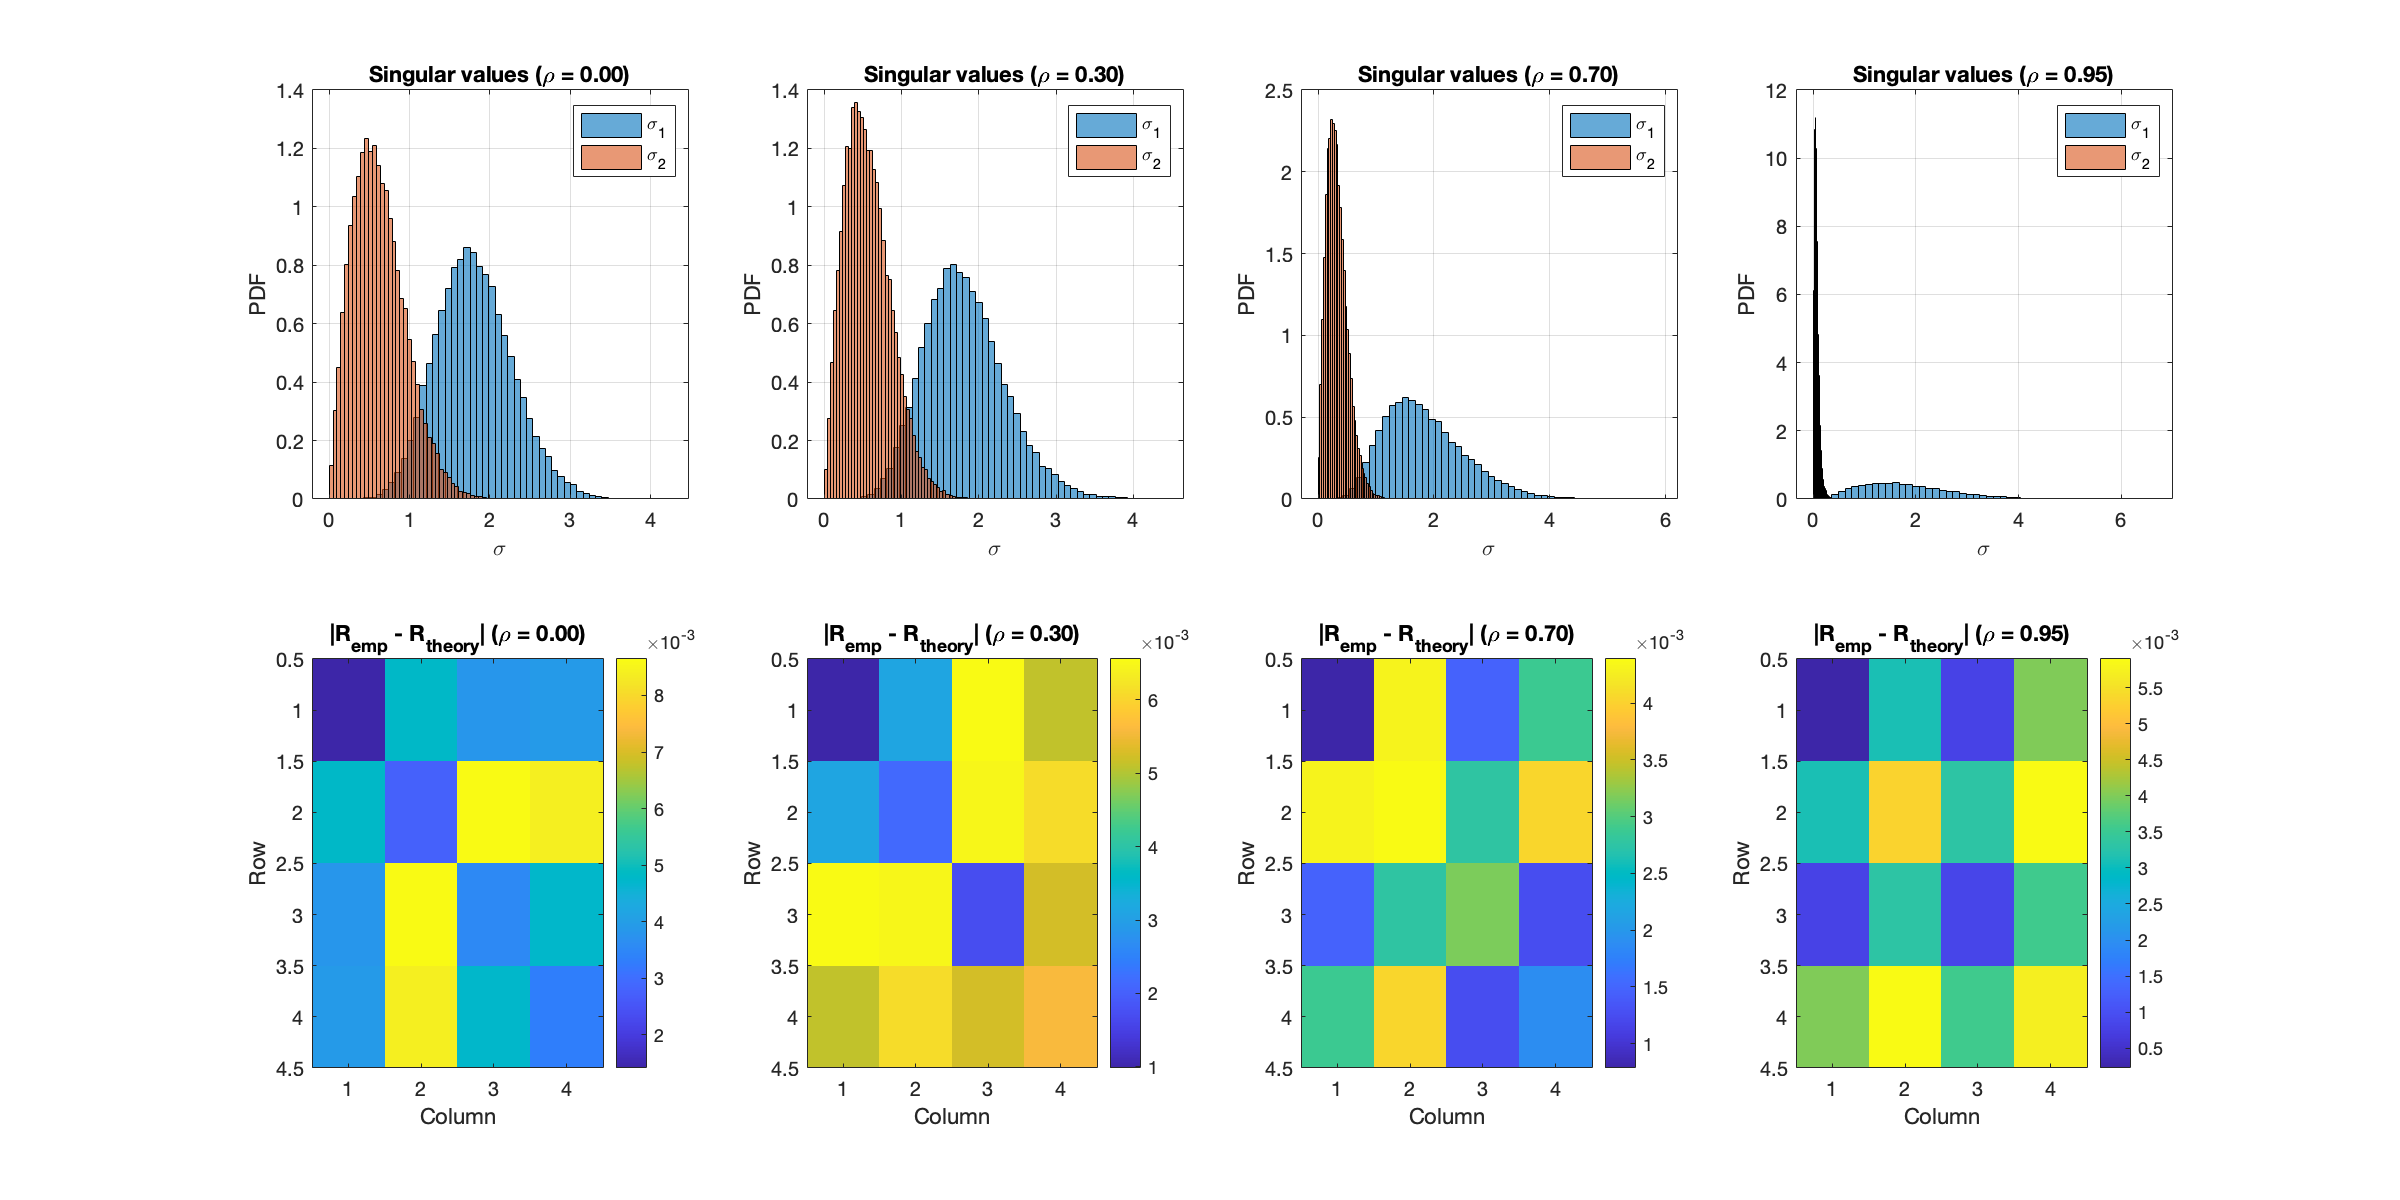


Nr = 2; Nt = 2;
N_trials = 50000;
 
rho_values = [0, 0.3, 0.7, 0.95];
 
figure('Name', 'Section 3: Kronecker Verification', 'Position', [100 100 1200 600]);
 
for idx = 1:length(rho_values)
    rho = rho_values(idx);
    R_tx = toeplitz([1, rho]);  % [1 rho; rho 1]
    R_rx = toeplitz([1, rho]);
    
    % Theoretical full correlation: R_tx^T kron R_rx
    R_full_theory = kron(R_tx.', R_rx);
    
    % Empirical: generate many channels, estimate correlation
    H_vec_all = zeros(Nr*Nt, N_trials);
    singular_vals = zeros(min(Nr,Nt), N_trials);
    
    for n = 1:N_trials
        H_iid = sqrt(0.5) * (randn(Nr,Nt) + 1j*randn(Nr,Nt));
        H = sqrtm(R_rx) * H_iid * sqrtm(R_tx);
        H_vec_all(:, n) = H(:);  % vectorize column-wise
        singular_vals(:, n) = svd(H);
    end
    
    R_full_empirical = (H_vec_all * H_vec_all') / N_trials;
    
    % Plot singular value distribution
    subplot(2, length(rho_values), idx);
    histogram(singular_vals(1,:), 50, 'Normalization', 'pdf'); hold on;
    histogram(singular_vals(2,:), 50, 'Normalization', 'pdf');
    title(sprintf('Singular values (\\rho = %.2f)', rho));
    xlabel('\sigma'); ylabel('PDF');
    legend('\sigma_1', '\sigma_2');
    grid on;
    
    % Plot correlation matrix comparison
    subplot(2, length(rho_values), idx + length(rho_values));
    imagesc(abs(R_full_empirical - R_full_theory));
    colorbar;
    title(sprintf('|R_{emp} - R_{theory}| (\\rho = %.2f)', rho));
    xlabel('Column'); ylabel('Row');
end

 
fprintf('=== SECTION 3: Kronecker Verification ===\n');

=== SECTION 3: Kronecker Verification ===


for idx = 1:length(rho_values)
    rho = rho_values(idx);
    R_tx = toeplitz([1, rho]);
    R_rx = toeplitz([1, rho]);
    R_full_theory = kron(R_tx.', R_rx);
    
    H_vec_all = zeros(Nr*Nt, N_trials);
    for n = 1:N_trials
        H_iid = sqrt(0.5) * (randn(Nr,Nt) + 1j*randn(Nr,Nt));
        H = sqrtm(R_rx) * H_iid * sqrtm(R_tx);
        H_vec_all(:, n) = H(:);
    end
    R_full_empirical = (H_vec_all * H_vec_all') / N_trials;
    
    fprintf('rho = %.2f: correlation matrix error = %.4f\n', ...
        rho, norm(R_full_empirical - R_full_theory, 'fro'));
end

rho = 0.00: correlation matrix error = 0.0158
rho = 0.30: correlation matrix error = 0.0143
rho = 0.70: correlation matrix error = 0.0173
rho = 0.95: correlation matrix error = 0.0066


fprintf('\n');

## Frequency-Selective MIMO Channel

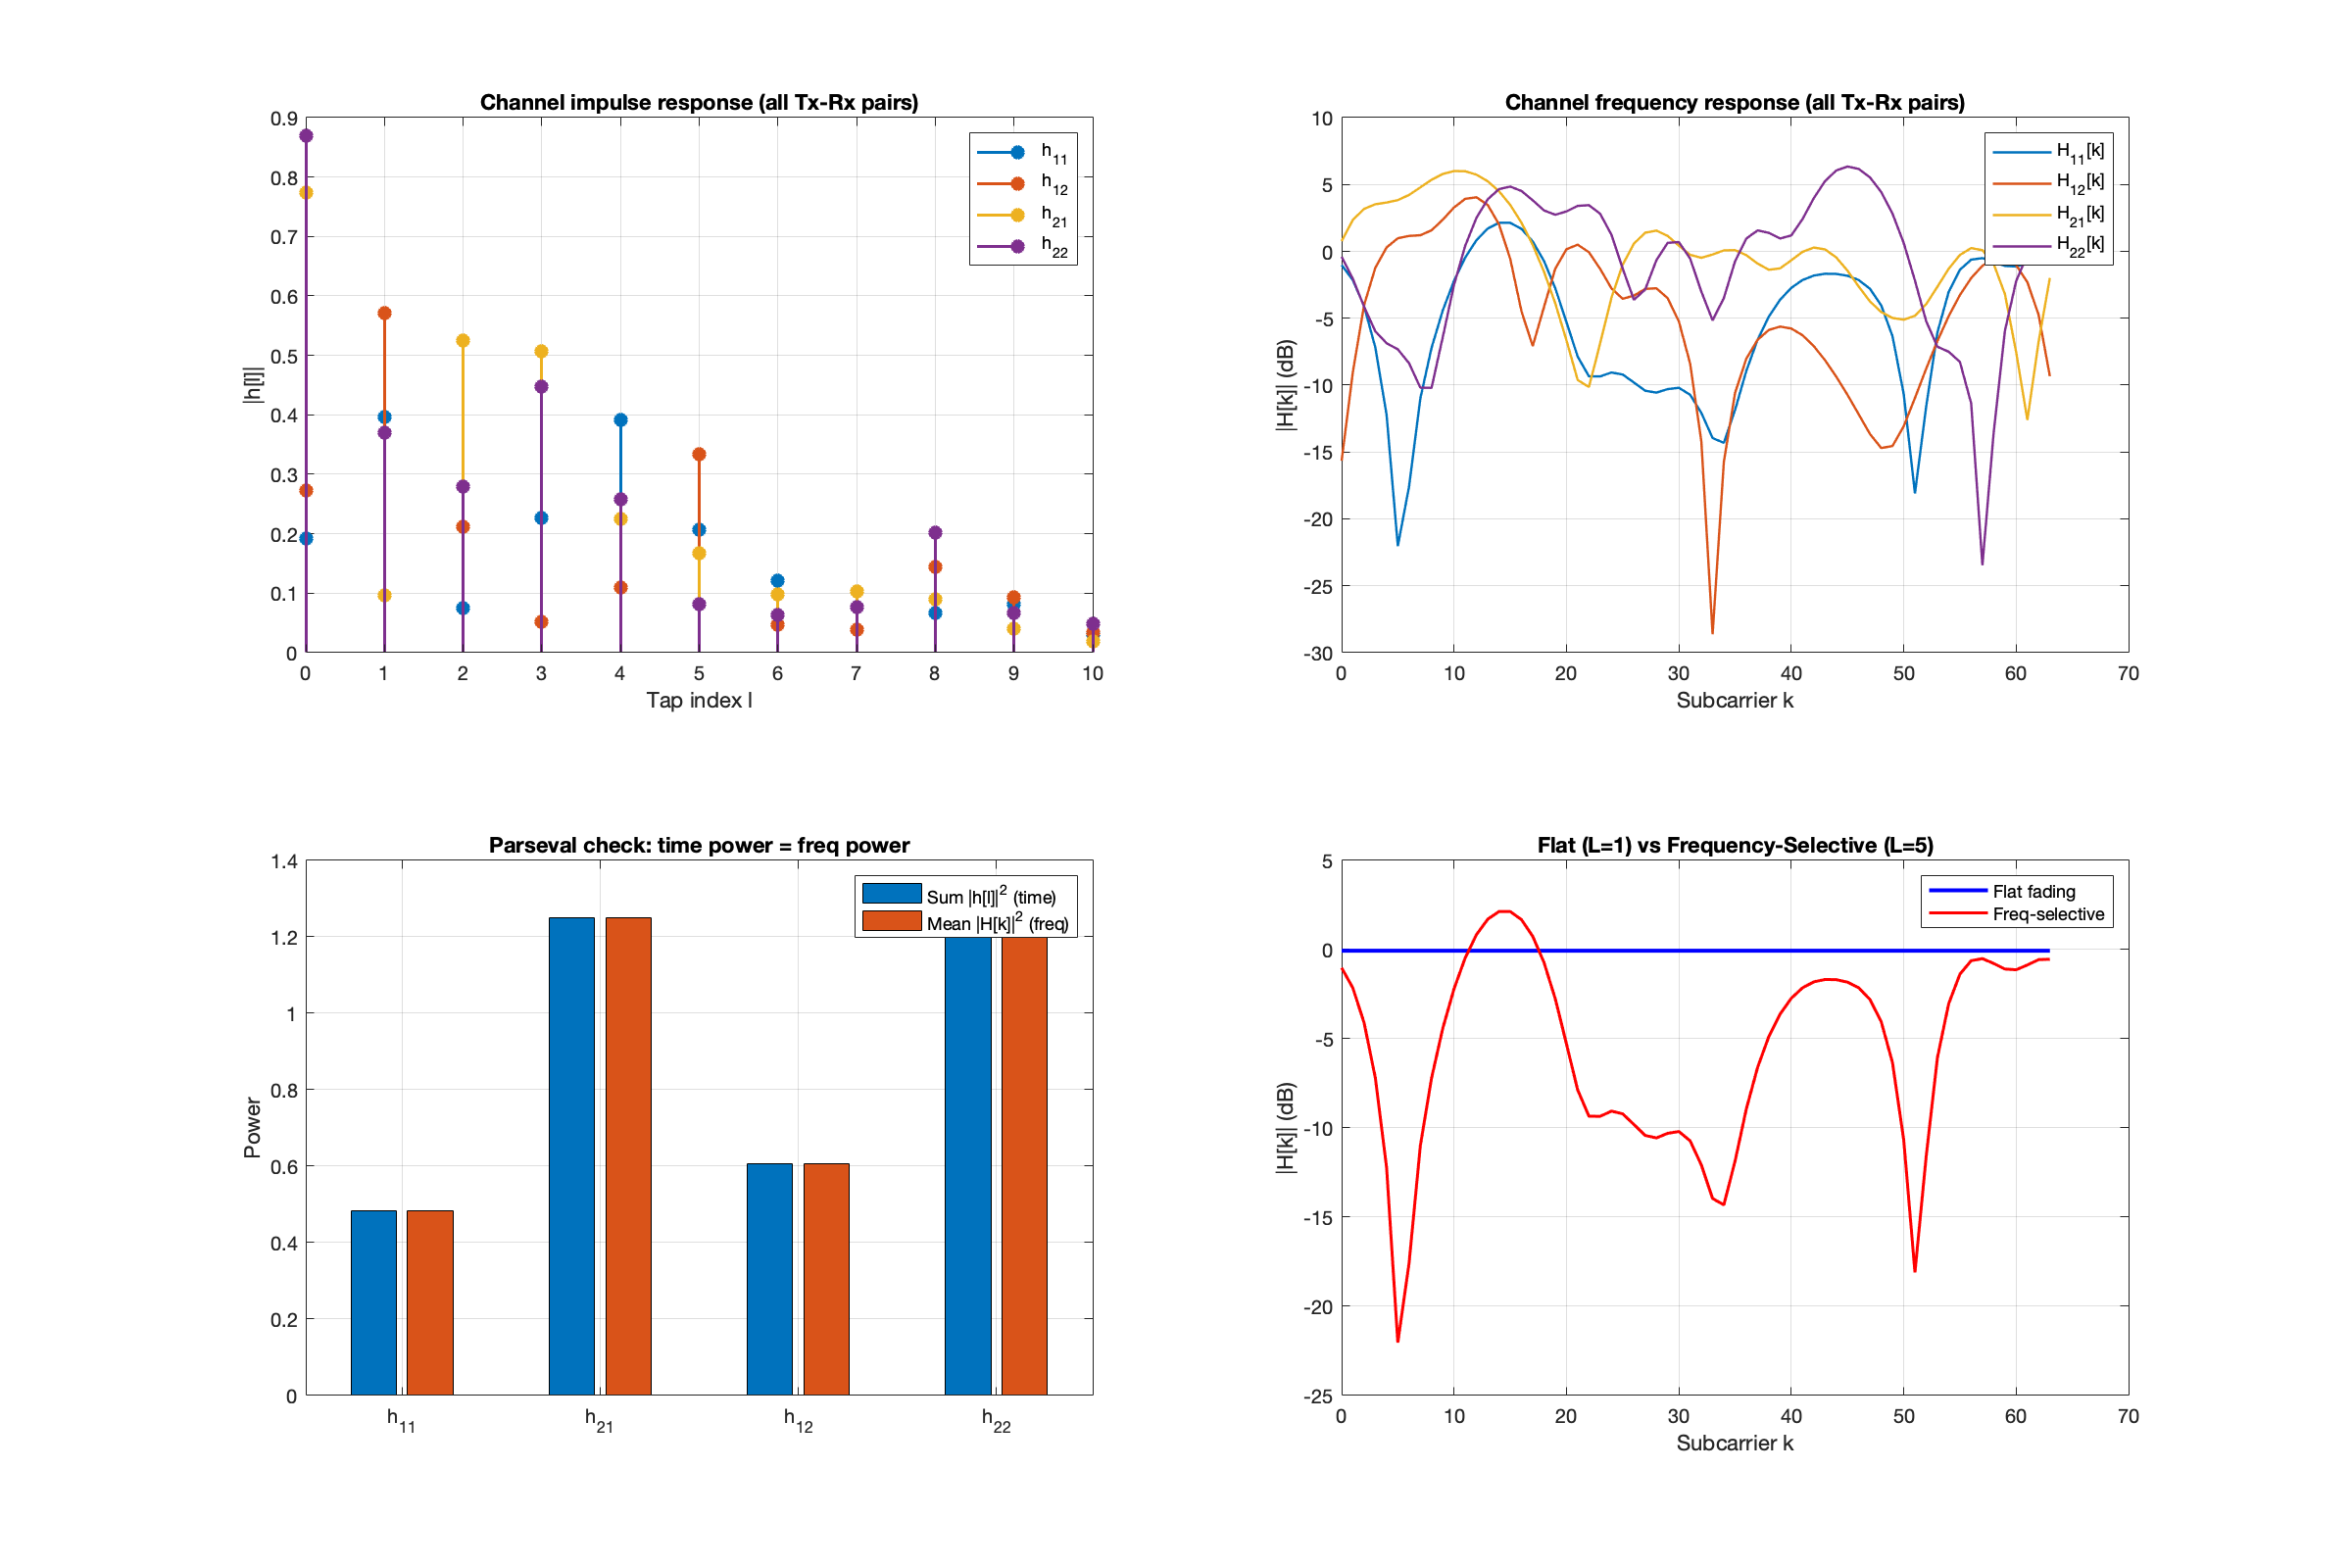


Nr = 2; Nt = 2; N = 64;
tau_d = 100e-9;   % 100 ns RMS delay spread
Ts = 50e-9;       % 50 ns sampling period
R_tx = eye(Nt);   % uncorrelated for now
R_rx = eye(Nr);
 
% Generate one realization using our function
[H_freq, h_taps] = freq_selective_mimo(Nr, Nt, N, tau_d, Ts, R_tx, R_rx);
L = size(h_taps, 3);
[pdp, ~] = exp_pdp(tau_d, Ts);
 
figure('Name', 'Section 4: Freq-Selective Channel', 'Position', [100 100 1200 800]);
 
% Plot tap impulse response for all Tx-Rx pairs
subplot(2,2,1);
for rx = 1:Nr
    for tx = 1:Nt
        stem(0:L-1, abs(squeeze(h_taps(rx,tx,:))), 'filled', 'LineWidth', 1.5);
        hold on;
    end
end
xlabel('Tap index l'); ylabel('|h[l]|');
title('Channel impulse response (all Tx-Rx pairs)');
legend('h_{11}', 'h_{12}', 'h_{21}', 'h_{22}');
grid on;
 
% Plot frequency response magnitude
subplot(2,2,2);
for rx = 1:Nr
    for tx = 1:Nt
        plot(0:N-1, 20*log10(abs(squeeze(H_freq(rx,tx,:)))), 'LineWidth', 1.2);
        hold on;
    end
end
xlabel('Subcarrier k'); ylabel('|H[k]| (dB)');
title('Channel frequency response (all Tx-Rx pairs)');
legend('H_{11}[k]', 'H_{12}[k]', 'H_{21}[k]', 'H_{22}[k]');
grid on;
 
% Verify: average power across subcarriers should match tap power
avg_power_freq = zeros(Nr, Nt);
for rx = 1:Nr
    for tx = 1:Nt
        avg_power_freq(rx,tx) = mean(abs(squeeze(H_freq(rx,tx,:))).^2);
    end
end
total_tap_power = zeros(Nr, Nt);
for rx = 1:Nr
    for tx = 1:Nt
        total_tap_power(rx,tx) = sum(abs(squeeze(h_taps(rx,tx,:))).^2);
    end
end
 
subplot(2,2,3);
bar([total_tap_power(:), avg_power_freq(:)]);
set(gca, 'XTickLabel', {'h_{11}', 'h_{21}', 'h_{12}', 'h_{22}'});
legend('Sum |h[l]|^2 (time)', 'Mean |H[k]|^2 (freq)');
title('Parseval check: time power = freq power');
ylabel('Power');
grid on;
 
% Compare flat vs frequency-selective
subplot(2,2,4);
% Flat: L=1
H_flat = sqrt(0.5) * (randn(Nr(1),Nt(1)) + 1j*randn(Nr(1),Nt(1)));
H_flat_freq = repmat(H_flat(1,1), [1 N]);  % same for all subcarriers
 
% Frequency-selective: already have H_freq
plot(0:N-1, 20*log10(abs(H_flat_freq)), 'b-', 'LineWidth', 2); hold on;
plot(0:N-1, 20*log10(abs(squeeze(H_freq(1,1,:)))), 'r-', 'LineWidth', 1.5);
xlabel('Subcarrier k'); ylabel('|H[k]| (dB)');
title('Flat (L=1) vs Frequency-Selective (L=5)');
legend('Flat fading', 'Freq-selective');
grid on;

 
fprintf('=== SECTION 4: Frequency-Selective Verification ===\n');

=== SECTION 4: Frequency-Selective Verification ===


fprintf('Config: %dx%d MIMO, L=%d taps, N=%d subcarriers, tau_rms=%g\n', Nr, Nt, L, N, tau_d);

Config: 2x2 MIMO, L=11 taps, N=64 subcarriers, tau_rms=1e-07


fprintf('\nParseval check (time power ≈ freq power):\n');


Parseval check (time power ≈ freq power):


for rx = 1:Nr
    for tx = 1:Nt
        fprintf('  h_%d%d: tap power = %.4f, freq power = %.4f\n', ...
            rx, tx, total_tap_power(rx,tx), avg_power_freq(rx,tx));
    end
end

  h_11: tap power = 0.4838, freq power = 0.4838
  h_12: tap power = 0.6056, freq power = 0.6056
  h_21: tap power = 1.2498, freq power = 1.2498
  h_22: tap power = 1.3026, freq power = 1.3026


fprintf('\n');


## Monte Carlo -- Verify Statistics over many realizations

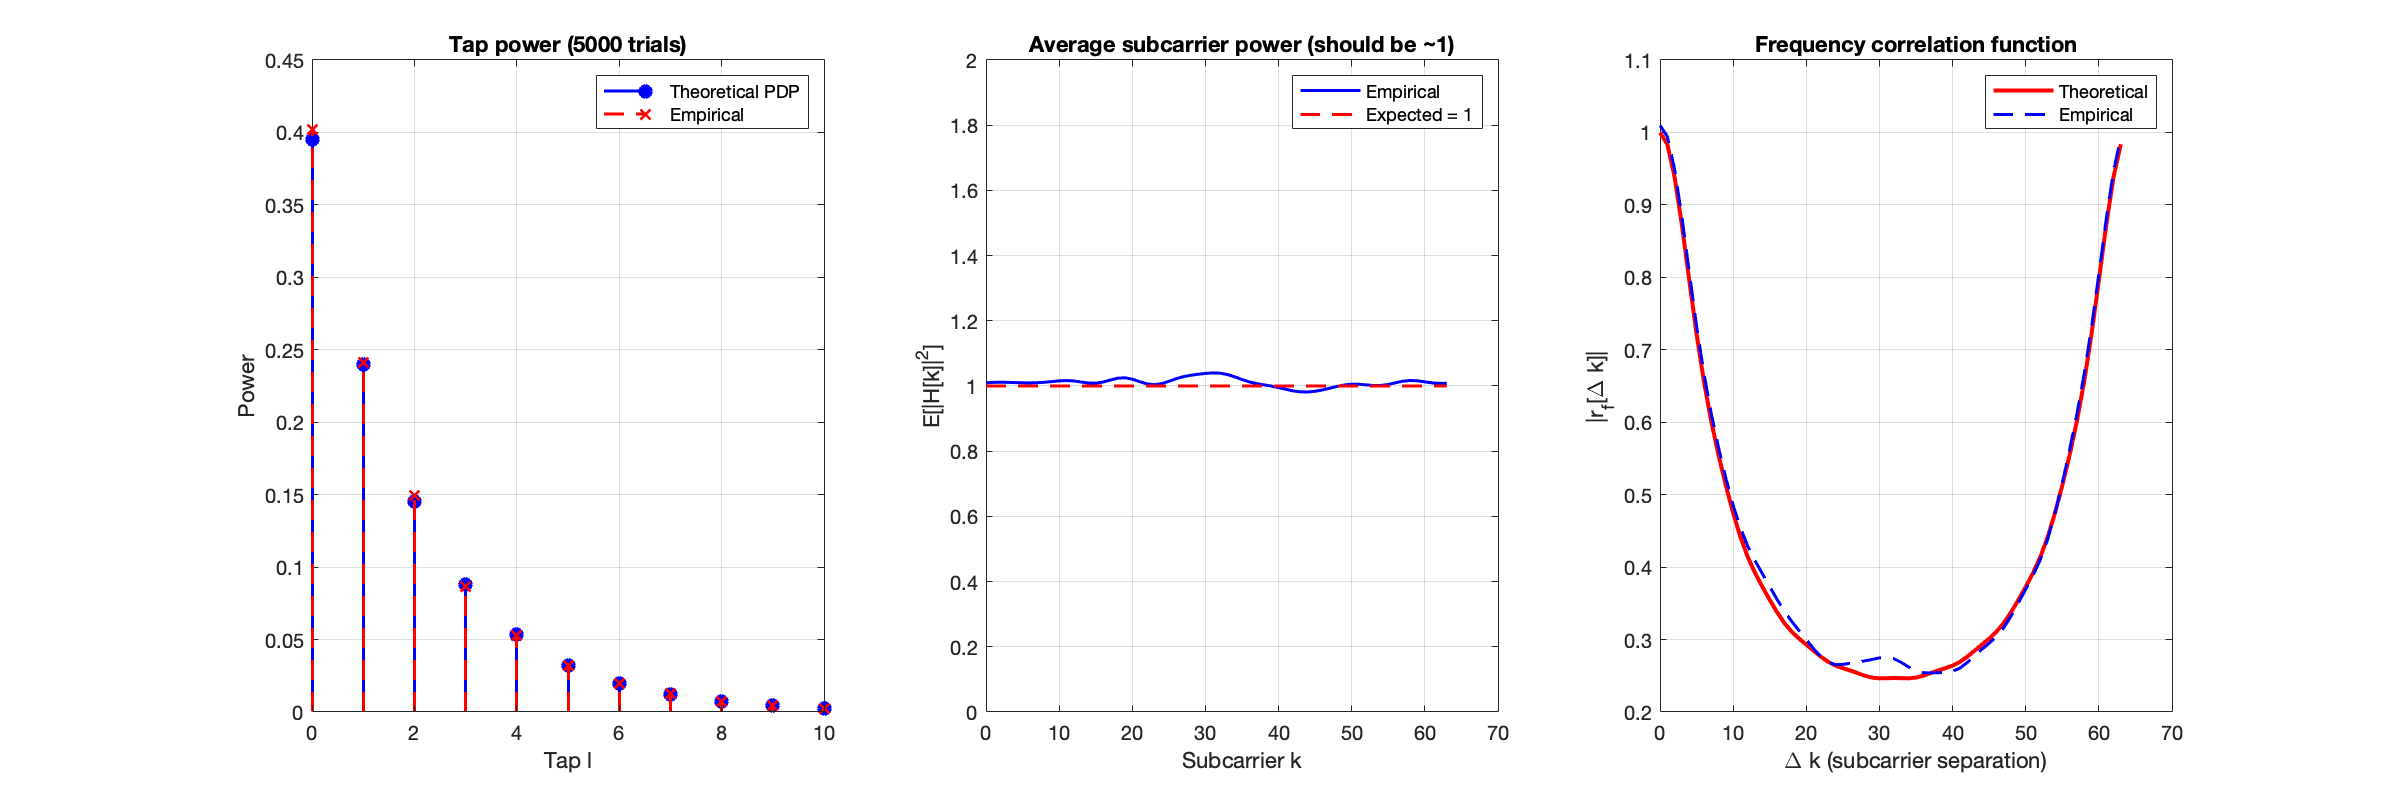


Nr = 2; Nt = 2; N = 64;
tau_d = 100e-9;   % 100 ns
Ts = 50e-9;       % 50 ns
N_trials = 5000;
 
[pdp, lmax] = exp_pdp(tau_d, Ts);
L = lmax + 1;
 
avg_tap_power = zeros(L, 1);
avg_freq_power = zeros(N, 1);
H11_all = zeros(N, N_trials);  % store H_11[k] for correlation analysis
 
for n = 1:N_trials
    [H_freq_tmp, h_taps_tmp] = freq_selective_mimo(Nr, Nt, N, tau_d, Ts, eye(Nt), eye(Nr));
    
    % Tap power
    for l = 1:L
        avg_tap_power(l) = avg_tap_power(l) + abs(h_taps_tmp(1,1,l))^2;
    end
    
    % Frequency domain
    H_f = squeeze(H_freq_tmp(1,1,:));
    avg_freq_power = avg_freq_power + abs(H_f).^2;
    H11_all(:, n) = H_f;
end
 
avg_tap_power = avg_tap_power / N_trials;
avg_freq_power = avg_freq_power / N_trials;
 
figure('Name', 'Section 5: Monte Carlo Verification', 'Position', [100 100 1200 400]);
 
% Tap powers vs PDP
subplot(1,3,1);
stem(0:L-1, pdp, 'bo-', 'filled', 'LineWidth', 1.5, 'MarkerSize', 6); hold on;
stem(0:L-1, avg_tap_power, 'rx--', 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('Tap l'); ylabel('Power');
title(sprintf('Tap power (%d trials)', N_trials));
legend('Theoretical PDP', 'Empirical');
grid on;
 
% Average frequency power (should be ~1 everywhere)
subplot(1,3,2);
plot(0:N-1, avg_freq_power, 'b-', 'LineWidth', 1.5); hold on;
plot([0 N-1], [1 1], 'r--', 'LineWidth', 1.5);
xlabel('Subcarrier k'); ylabel('E[|H[k]|^2]');
title('Average subcarrier power (should be ~1)');
legend('Empirical', 'Expected = 1');
grid on; ylim([0 2]);
 
% Frequency correlation
% Theoretical: r_f[delta_k] = sum_l pdp[l] * exp(-j*2*pi*l*delta_k/N)
R_empirical = (H11_all * H11_all') / N_trials;
r_f_empirical = R_empirical(1, :);  % correlation of subcarrier 0 with all others
 
delta_k = 0:N-1;
r_f_theory = zeros(1, N);
for l = 0:L-1
    r_f_theory = r_f_theory + pdp(l+1) * exp(-1j*2*pi*l*delta_k/N);
end
 
subplot(1,3,3);
plot(delta_k, abs(r_f_theory), 'r-', 'LineWidth', 2); hold on;
plot(delta_k, abs(r_f_empirical), 'b--', 'LineWidth', 1.5);
xlabel('\Delta k (subcarrier separation)'); ylabel('|r_f[\Delta k]|');
title('Frequency correlation function');
legend('Theoretical', 'Empirical');
grid on;

 
fprintf('=== SECTION 5: Monte Carlo Verification ===\n');

=== SECTION 5: Monte Carlo Verification ===


fprintf('Average subcarrier power: %.4f (should be ~1)\n', mean(avg_freq_power));

Average subcarrier power: 1.0109 (should be ~1)


fprintf('Frequency correlation error: %.4f\n', norm(r_f_theory - r_f_empirical));

Frequency correlation error: 3.4208


fprintf('\n');


## FWGN - Time Varying Fading

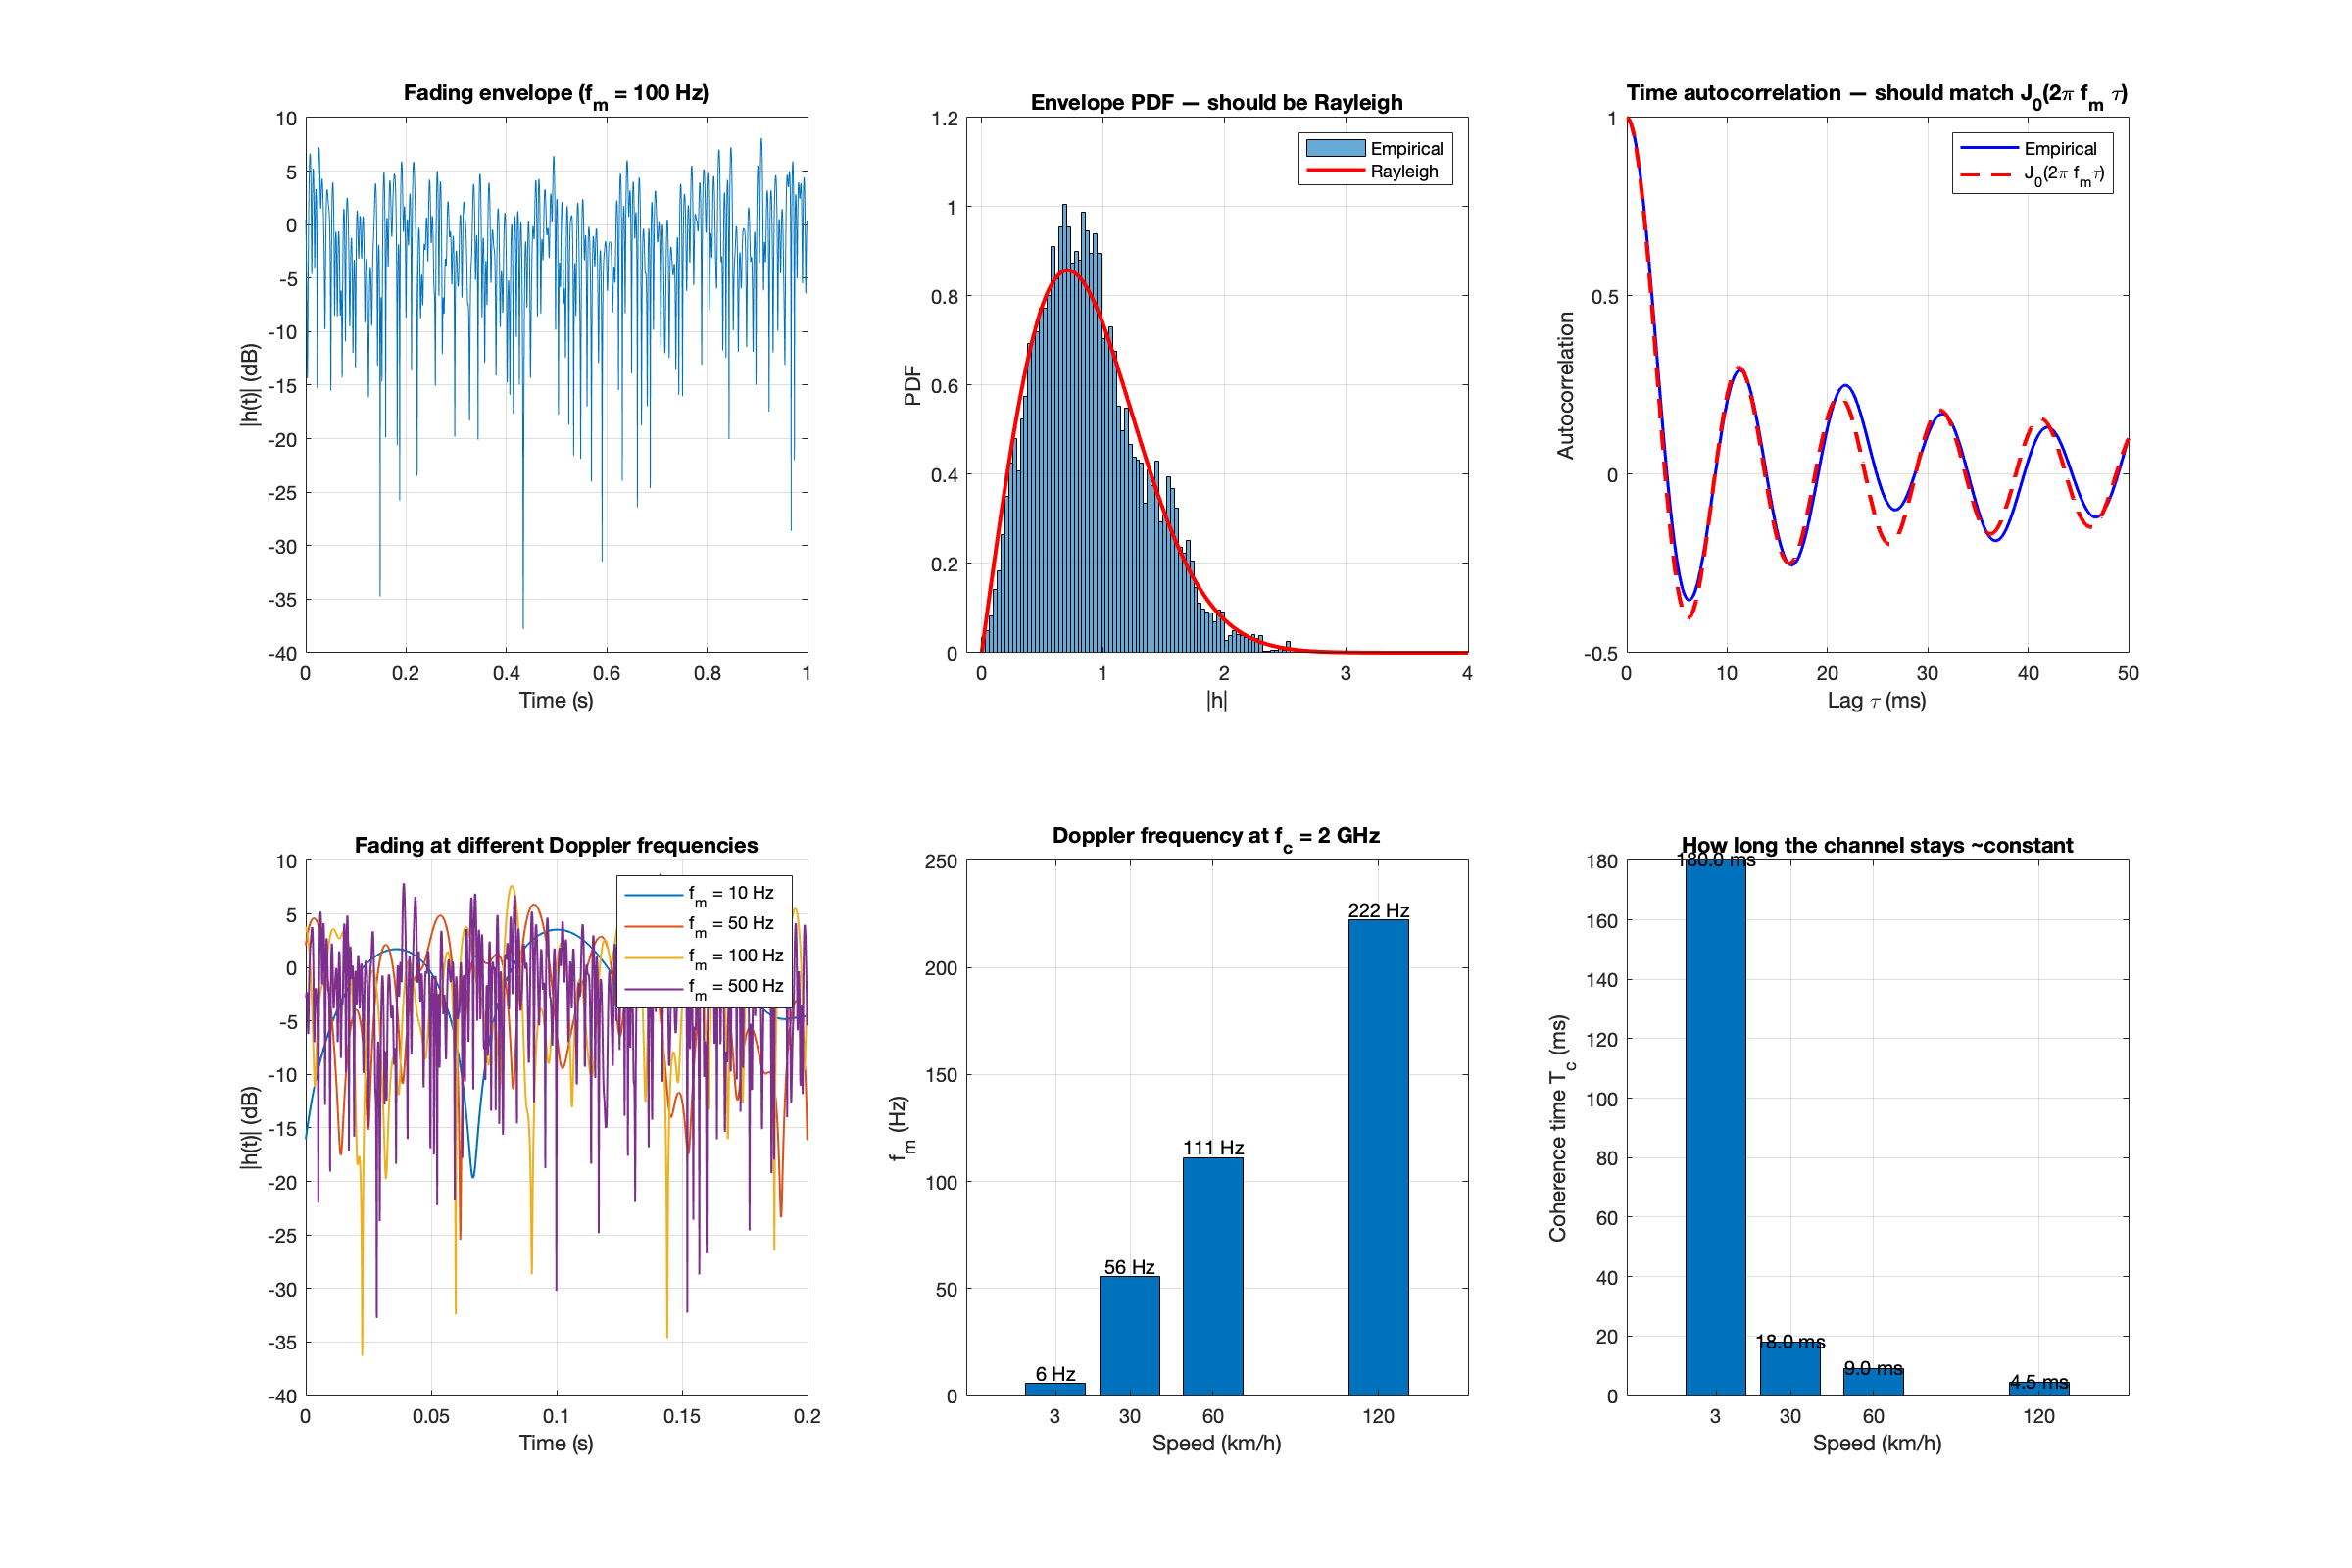


fm = 100;              % max Doppler frequency [Hz] (e.g., walking speed at 2 GHz)
fs_fading = 10000;     % fading sampling rate [Hz] (one sample per OFDM symbol)
N_samples_fading = 10000;  % number of time snapshots
 
% Generate one fading sequence using FWGN
[h_fading, ~, ~, ~] = fwgn_model(fm, fs_fading, N_samples_fading);
 
% --- Verify: envelope should be Rayleigh ---
figure('Name', 'Section 5b: FWGN Verification', 'Position', [100 100 1200 800]);
 
subplot(2,3,1);
t_axis = (0:N_samples_fading-1) / fs_fading;
plot(t_axis, 20*log10(abs(h_fading)));
xlabel('Time (s)'); ylabel('|h(t)| (dB)');
title(sprintf('Fading envelope (f_m = %d Hz)', fm));
grid on;
 
subplot(2,3,2);
histogram(abs(h_fading), 80, 'Normalization', 'pdf'); hold on;
r = linspace(0, 4, 200);
rayleigh_pdf = 2 * r .* exp(-r.^2);
plot(r, rayleigh_pdf, 'r-', 'LineWidth', 2);
title('Envelope PDF — should be Rayleigh');
xlabel('|h|'); ylabel('PDF');
legend('Empirical', 'Rayleigh');
grid on;
 
% --- Verify: autocorrelation should be J_0(2*pi*fm*tau) ---
max_lag = min(500, N_samples_fading-1);
[acf, lags] = xcorr(h_fading, max_lag, 'coeff');
acf = acf(max_lag+1:end);  % positive lags only
tau = (0:max_lag) / fs_fading;
 
% Theoretical: Bessel function J_0
acf_theory = besselj(0, 2*pi*fm*tau);
 
subplot(2,3,3);
plot(tau*1000, real(acf), 'b-', 'LineWidth', 1.5); hold on;
plot(tau*1000, acf_theory, 'r--', 'LineWidth', 1.5);
xlabel('Lag \tau (ms)'); ylabel('Autocorrelation');
title('Time autocorrelation — should match J_0(2\pi f_m \tau)');
legend('Empirical', 'J_0(2\pi f_m\tau)');
grid on;
 
% --- Compare different Doppler frequencies ---
fm_values = [10, 50, 100, 500];  % different speeds
subplot(2,3,4);
hold on;
for i = 1:length(fm_values)
    h_tmp = fwgn_model(fm_values(i), fs_fading, 2000);
    plot((0:1999)/fs_fading, 20*log10(abs(h_tmp)), 'LineWidth', 1);
end
xlabel('Time (s)'); ylabel('|h(t)| (dB)');
title('Fading at different Doppler frequencies');
legend(arrayfun(@(f) sprintf('f_m = %d Hz', f), fm_values, 'UniformOutput', false));
grid on;
 
% --- Physical interpretation ---
fc = 2e9;  % 2 GHz carrier
c = 3e8;   % speed of light
subplot(2,3,5);
speeds_kmh = [3, 30, 60, 120];
speeds_ms = speeds_kmh / 3.6;
fm_from_speed = speeds_ms * fc / c;
bar(speeds_kmh, fm_from_speed);
xlabel('Speed (km/h)'); ylabel('f_m (Hz)');
title(sprintf('Doppler frequency at f_c = %g GHz', fc/1e9));
for i = 1:length(speeds_kmh)
    text(speeds_kmh(i), fm_from_speed(i)+5, sprintf('%.0f Hz', fm_from_speed(i)), ...
        'HorizontalAlignment', 'center');
end
grid on;
 
% --- Coherence time ---
subplot(2,3,6);
Tc = 1 ./ fm_from_speed;  % approximate coherence time
bar(speeds_kmh, Tc*1000);
xlabel('Speed (km/h)'); ylabel('Coherence time T_c (ms)');
title('How long the channel stays ~constant');
for i = 1:length(speeds_kmh)
    text(speeds_kmh(i), Tc(i)*1000+0.5, sprintf('%.1f ms', Tc(i)*1000), ...
        'HorizontalAlignment', 'center');
end
grid on;

 
fprintf('=== SECTION 5b: FWGN Verification ===\n');

=== SECTION 5b: FWGN Verification ===


fprintf('f_m = %d Hz, %d samples at fs = %d Hz\n', fm, N_samples_fading, fs_fading);

f_m = 100 Hz, 10000 samples at fs = 10000 Hz


fprintf('Mean |h|^2: %.4f (should be ~1)\n', mean(abs(h_fading).^2));

Mean |h|^2: 0.9902 (should be ~1)


fprintf('Autocorrelation error vs J_0: %.4f\n', norm(real(acf(1:100)) - acf_theory(1:100)));

Autocorrelation error vs J_0: 0.3676


fprintf('\nPhysical interpretation (fc = %.1f GHz):\n', fc/1e9);


Physical interpretation (fc = 2.0 GHz):


for i = 1:length(speeds_kmh)
    fprintf('  %3d km/h → f_m = %5.1f Hz, T_c ≈ %.1f ms\n', ...
        speeds_kmh(i), fm_from_speed(i), Tc(i)*1000);
end

    3 km/h → f_m =   5.6 Hz, T_c ≈ 180.0 ms
   30 km/h → f_m =  55.6 Hz, T_c ≈ 18.0 ms
   60 km/h → f_m = 111.1 Hz, T_c ≈ 9.0 ms
  120 km/h → f_m = 222.2 Hz, T_c ≈ 4.5 ms


fprintf('\n');

## Time-Varying Frequency selective MIMO Channel

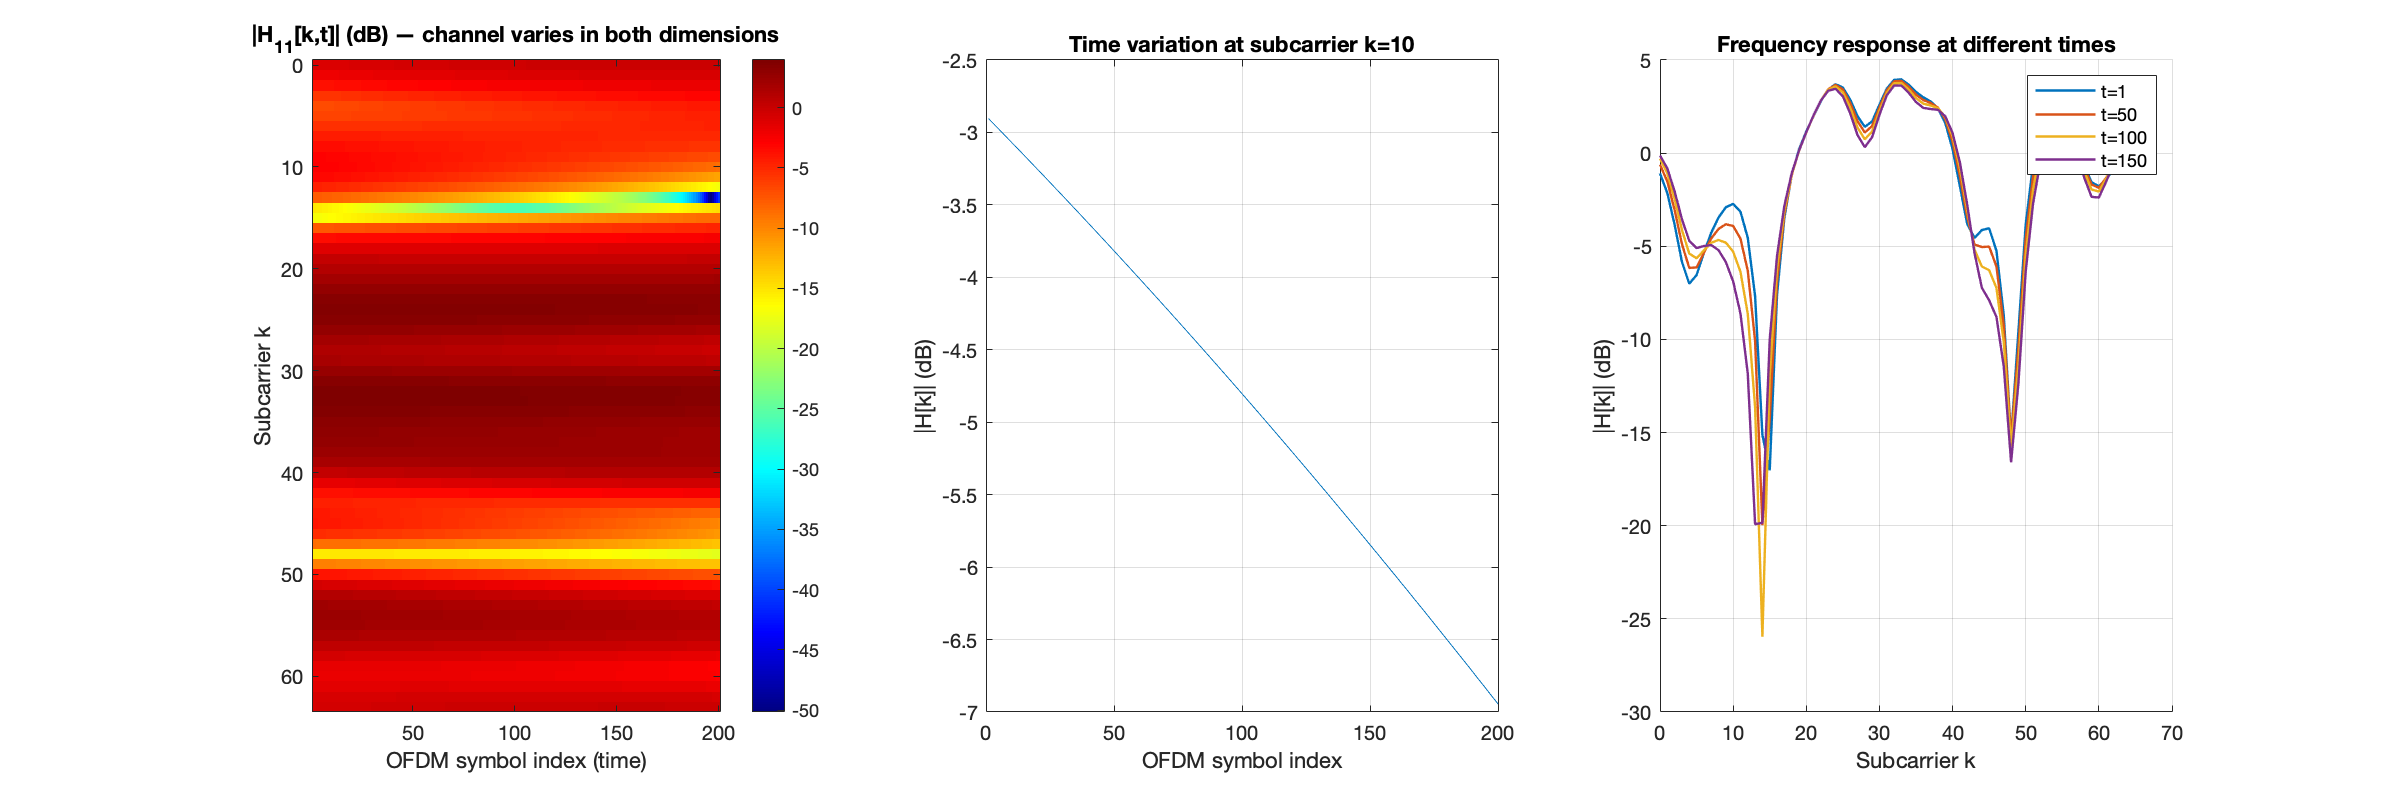

Nr = 2; Nt = 2; N = 64; T = 200;
tau_d = 100e-9;
Ts = 50e-9;
fm = 100;
fs_ofdm = 1 / (N*Ts + 16*Ts);  % OFDM symbol rate (including CP of 16 samples)
 
[pdp, lmax] = exp_pdp(tau_d, Ts);
L = lmax + 1;
 
% Generate time-varying taps: each tap is FWGN-correlated over T symbols
h_taps_tv = zeros(Nr, Nt, L, T);
for rx = 1:Nr
    for tx = 1:Nt
        for l = 1:L
            h_time = fwgn_model(fm, fs_ofdm, T);  % T correlated samples
            h_taps_tv(rx, tx, l, :) = sqrt(pdp(l)) * h_time;
        end
    end
end
 
% FFT across taps at each time instant
H_freq_tv = zeros(Nr, Nt, N, T);
for t = 1:T
    for rx = 1:Nr
        for tx = 1:Nt
            h_vec = squeeze(h_taps_tv(rx, tx, :, t));
            H_freq_tv(rx, tx, :, t) = fft(h_vec, N);
        end
    end
end
 
figure('Name', 'Section 5c: Time-Varying Channel', 'Position', [100 100 1200 400]);
 
% Waterfall: |H[k,t]| for one Tx-Rx pair
subplot(1,3,1);
H11_mag = squeeze(20*log10(abs(H_freq_tv(1,1,:,:))));
imagesc(1:T, 0:N-1, H11_mag);
xlabel('OFDM symbol index (time)');
ylabel('Subcarrier k');
title('|H_{11}[k,t]| (dB) — channel varies in both dimensions');
colorbar; colormap('jet');
 
% Time variation at one subcarrier
subplot(1,3,2);
k_plot = 10;
plot(1:T, squeeze(20*log10(abs(H_freq_tv(1,1,k_plot,:)))));
xlabel('OFDM symbol index'); ylabel('|H[k]| (dB)');
title(sprintf('Time variation at subcarrier k=%d', k_plot));
grid on;
 
% Frequency response at different times
subplot(1,3,3);
t_indices = [1, 50, 100, 150];
hold on;
for t = t_indices
    plot(0:N-1, 20*log10(abs(squeeze(H_freq_tv(1,1,:,t)))), 'LineWidth', 1.2);
end
xlabel('Subcarrier k'); ylabel('|H[k]| (dB)');
title('Frequency response at different times');
legend(arrayfun(@(t) sprintf('t=%d', t), t_indices, 'UniformOutput', false));
grid on;

 
fprintf('=== SECTION 5c: Time-Varying Freq-Selective Channel ===\n');

=== SECTION 5c: Time-Varying Freq-Selective Channel ===


fprintf('Config: %dx%d MIMO, N=%d, L=%d, T=%d symbols\n', Nr, Nt, N, L, T);

Config: 2x2 MIMO, N=64, L=11, T=200 symbols


fprintf('f_m = %d Hz, OFDM symbol rate = %.0f Hz\n', fm, fs_ofdm);

f_m = 100 Hz, OFDM symbol rate = 250000 Hz


fprintf('Channel dimension: Nr x Nt x N x T = %d x %d x %d x %d\n', Nr, Nt, N, T);

Channel dimension: Nr x Nt x N x T = 2 x 2 x 64 x 200


fprintf('This is the full doubly-selective MIMO-OFDM channel.\n');

This is the full doubly-selective MIMO-OFDM channel.


fprintf('\n');
